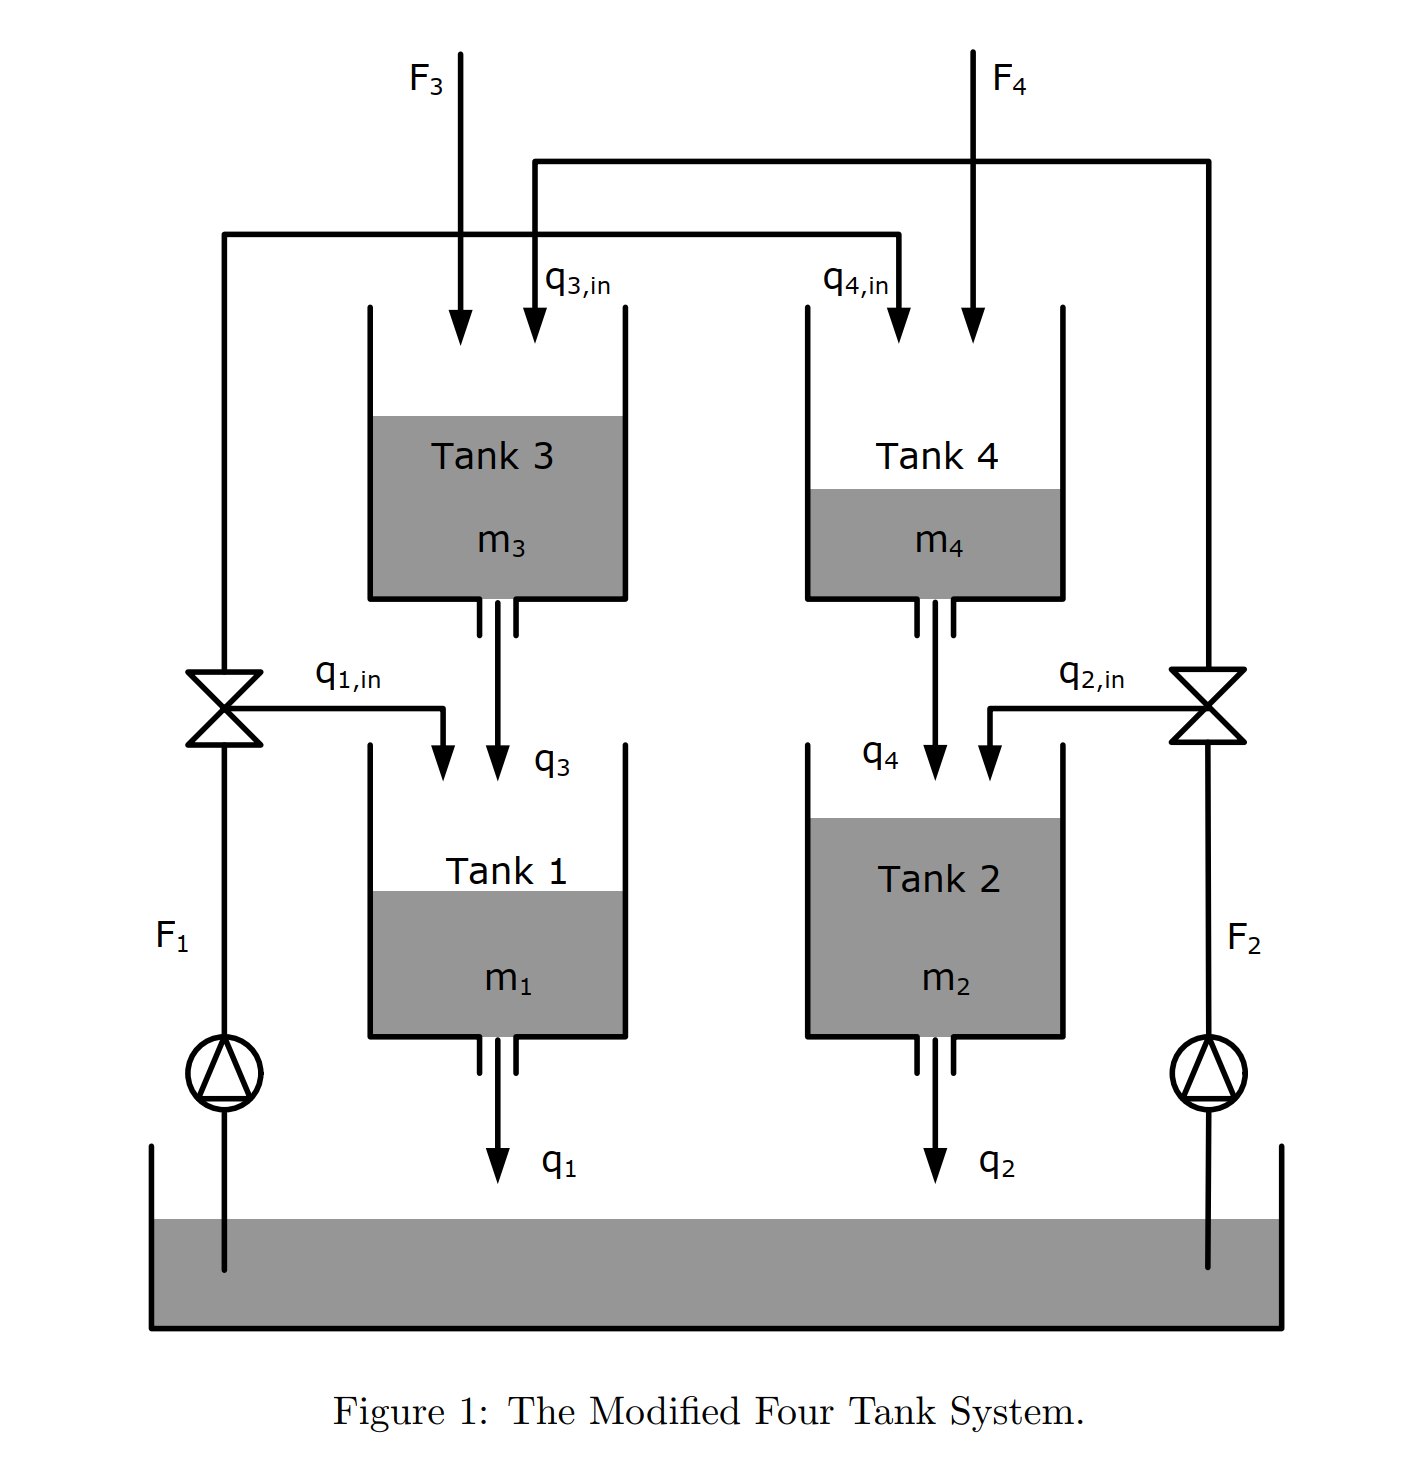

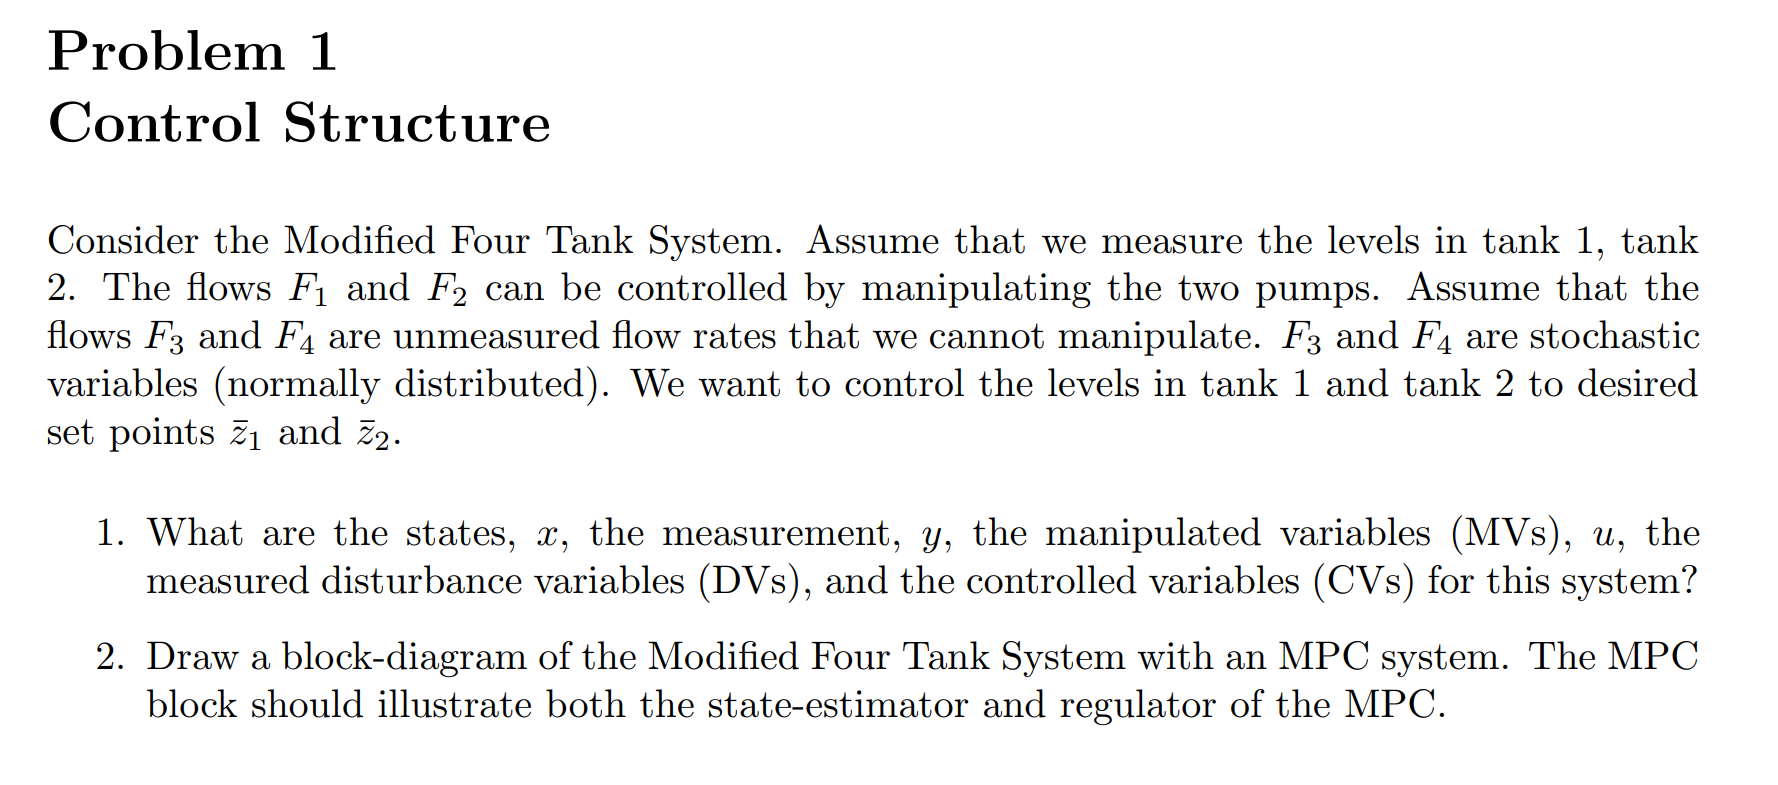

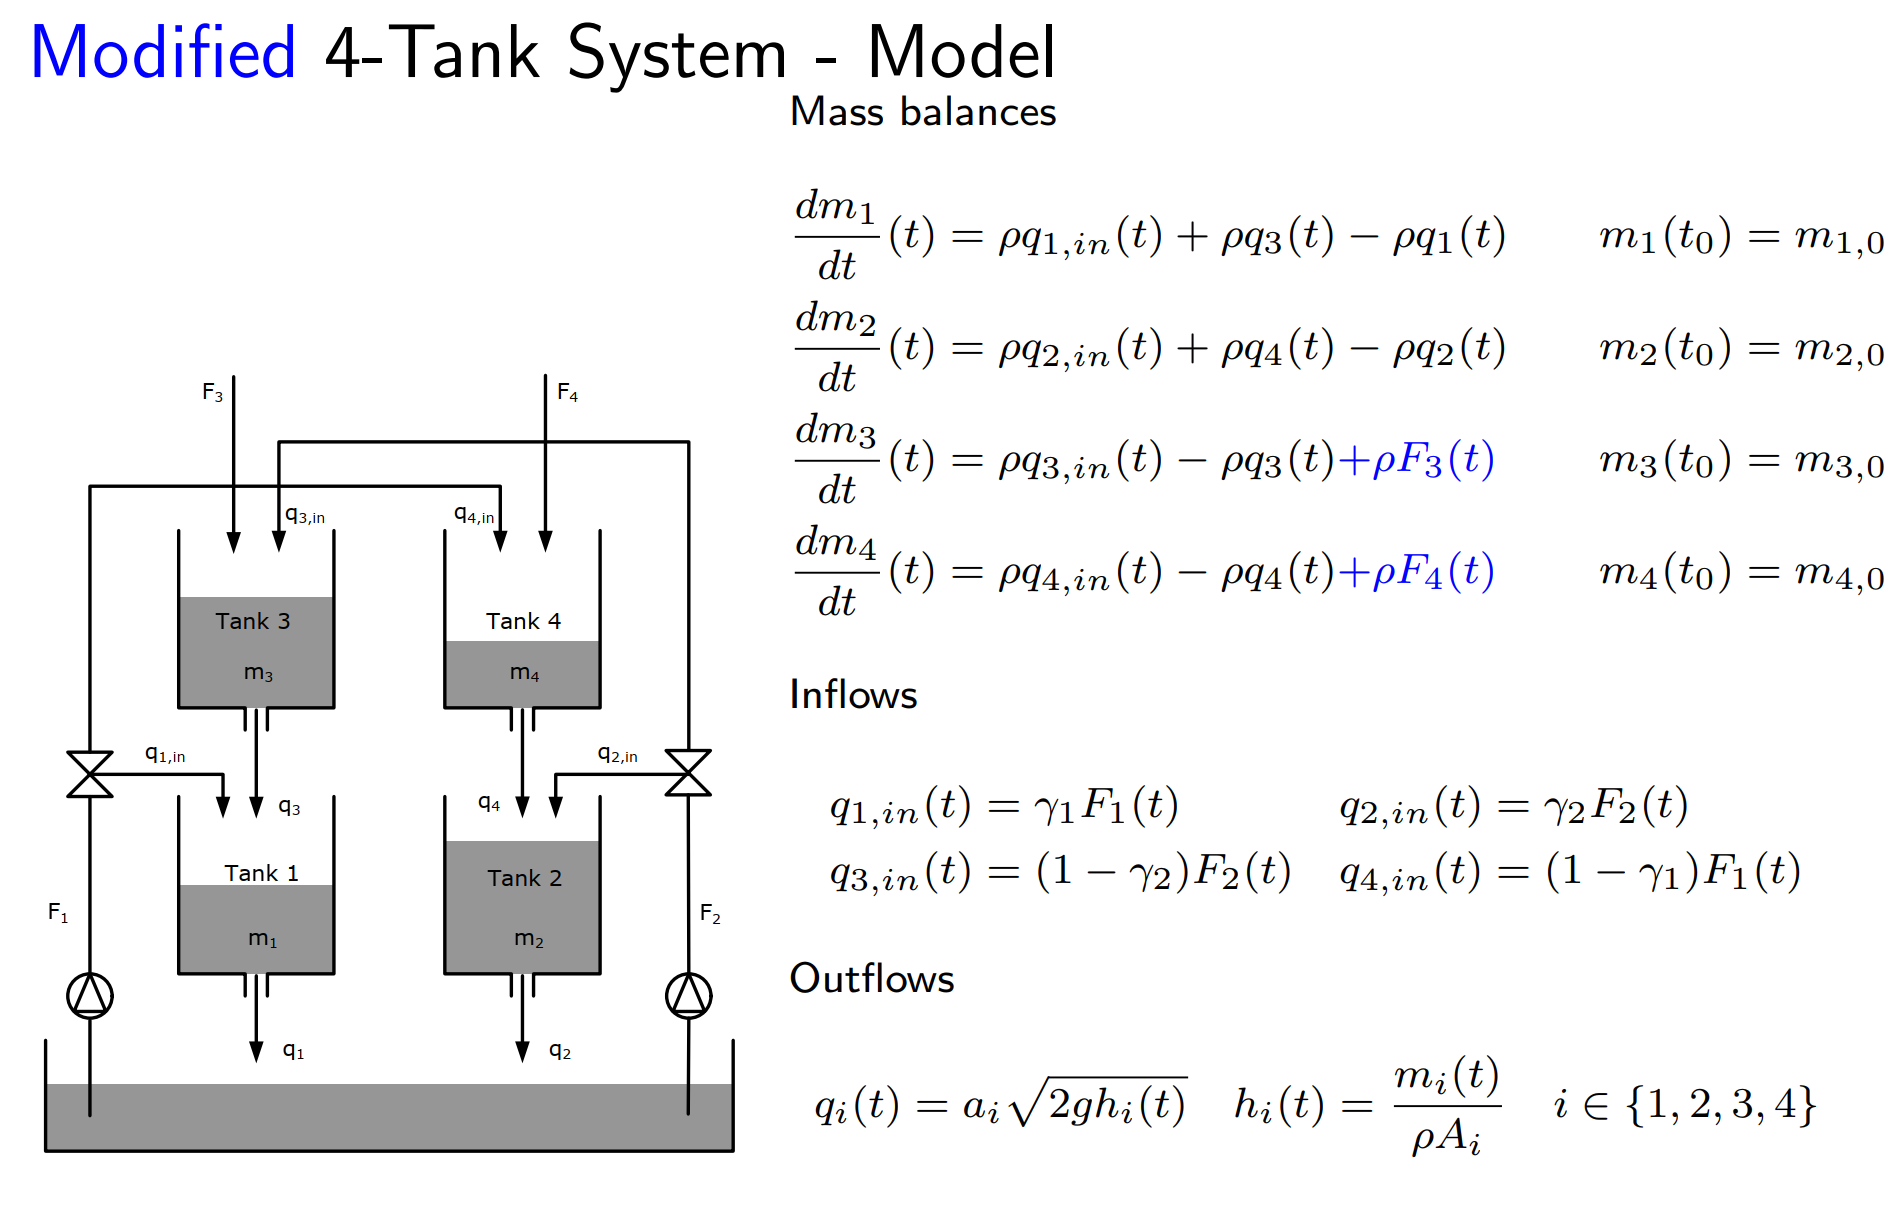

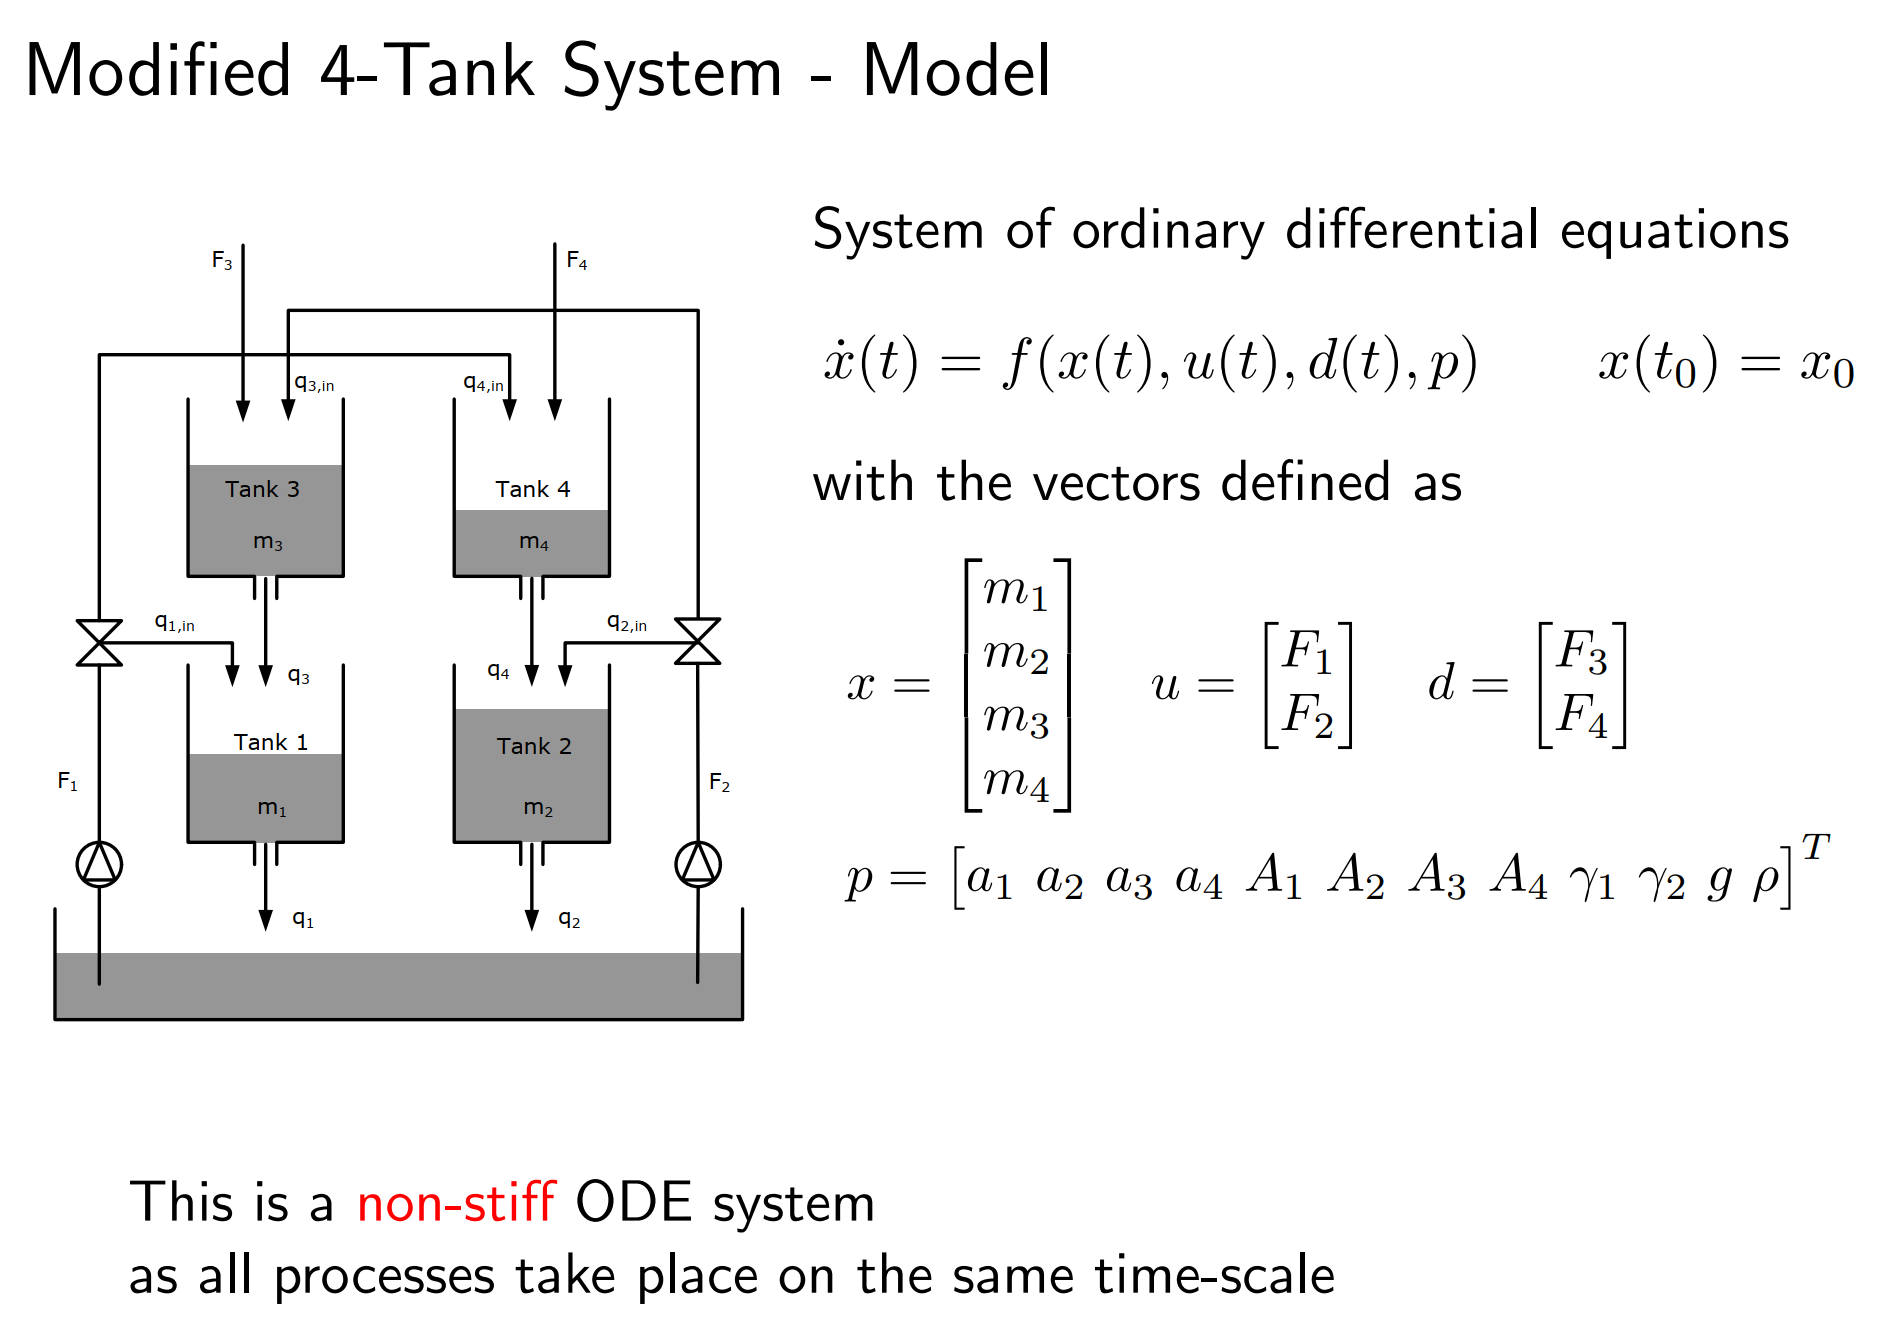

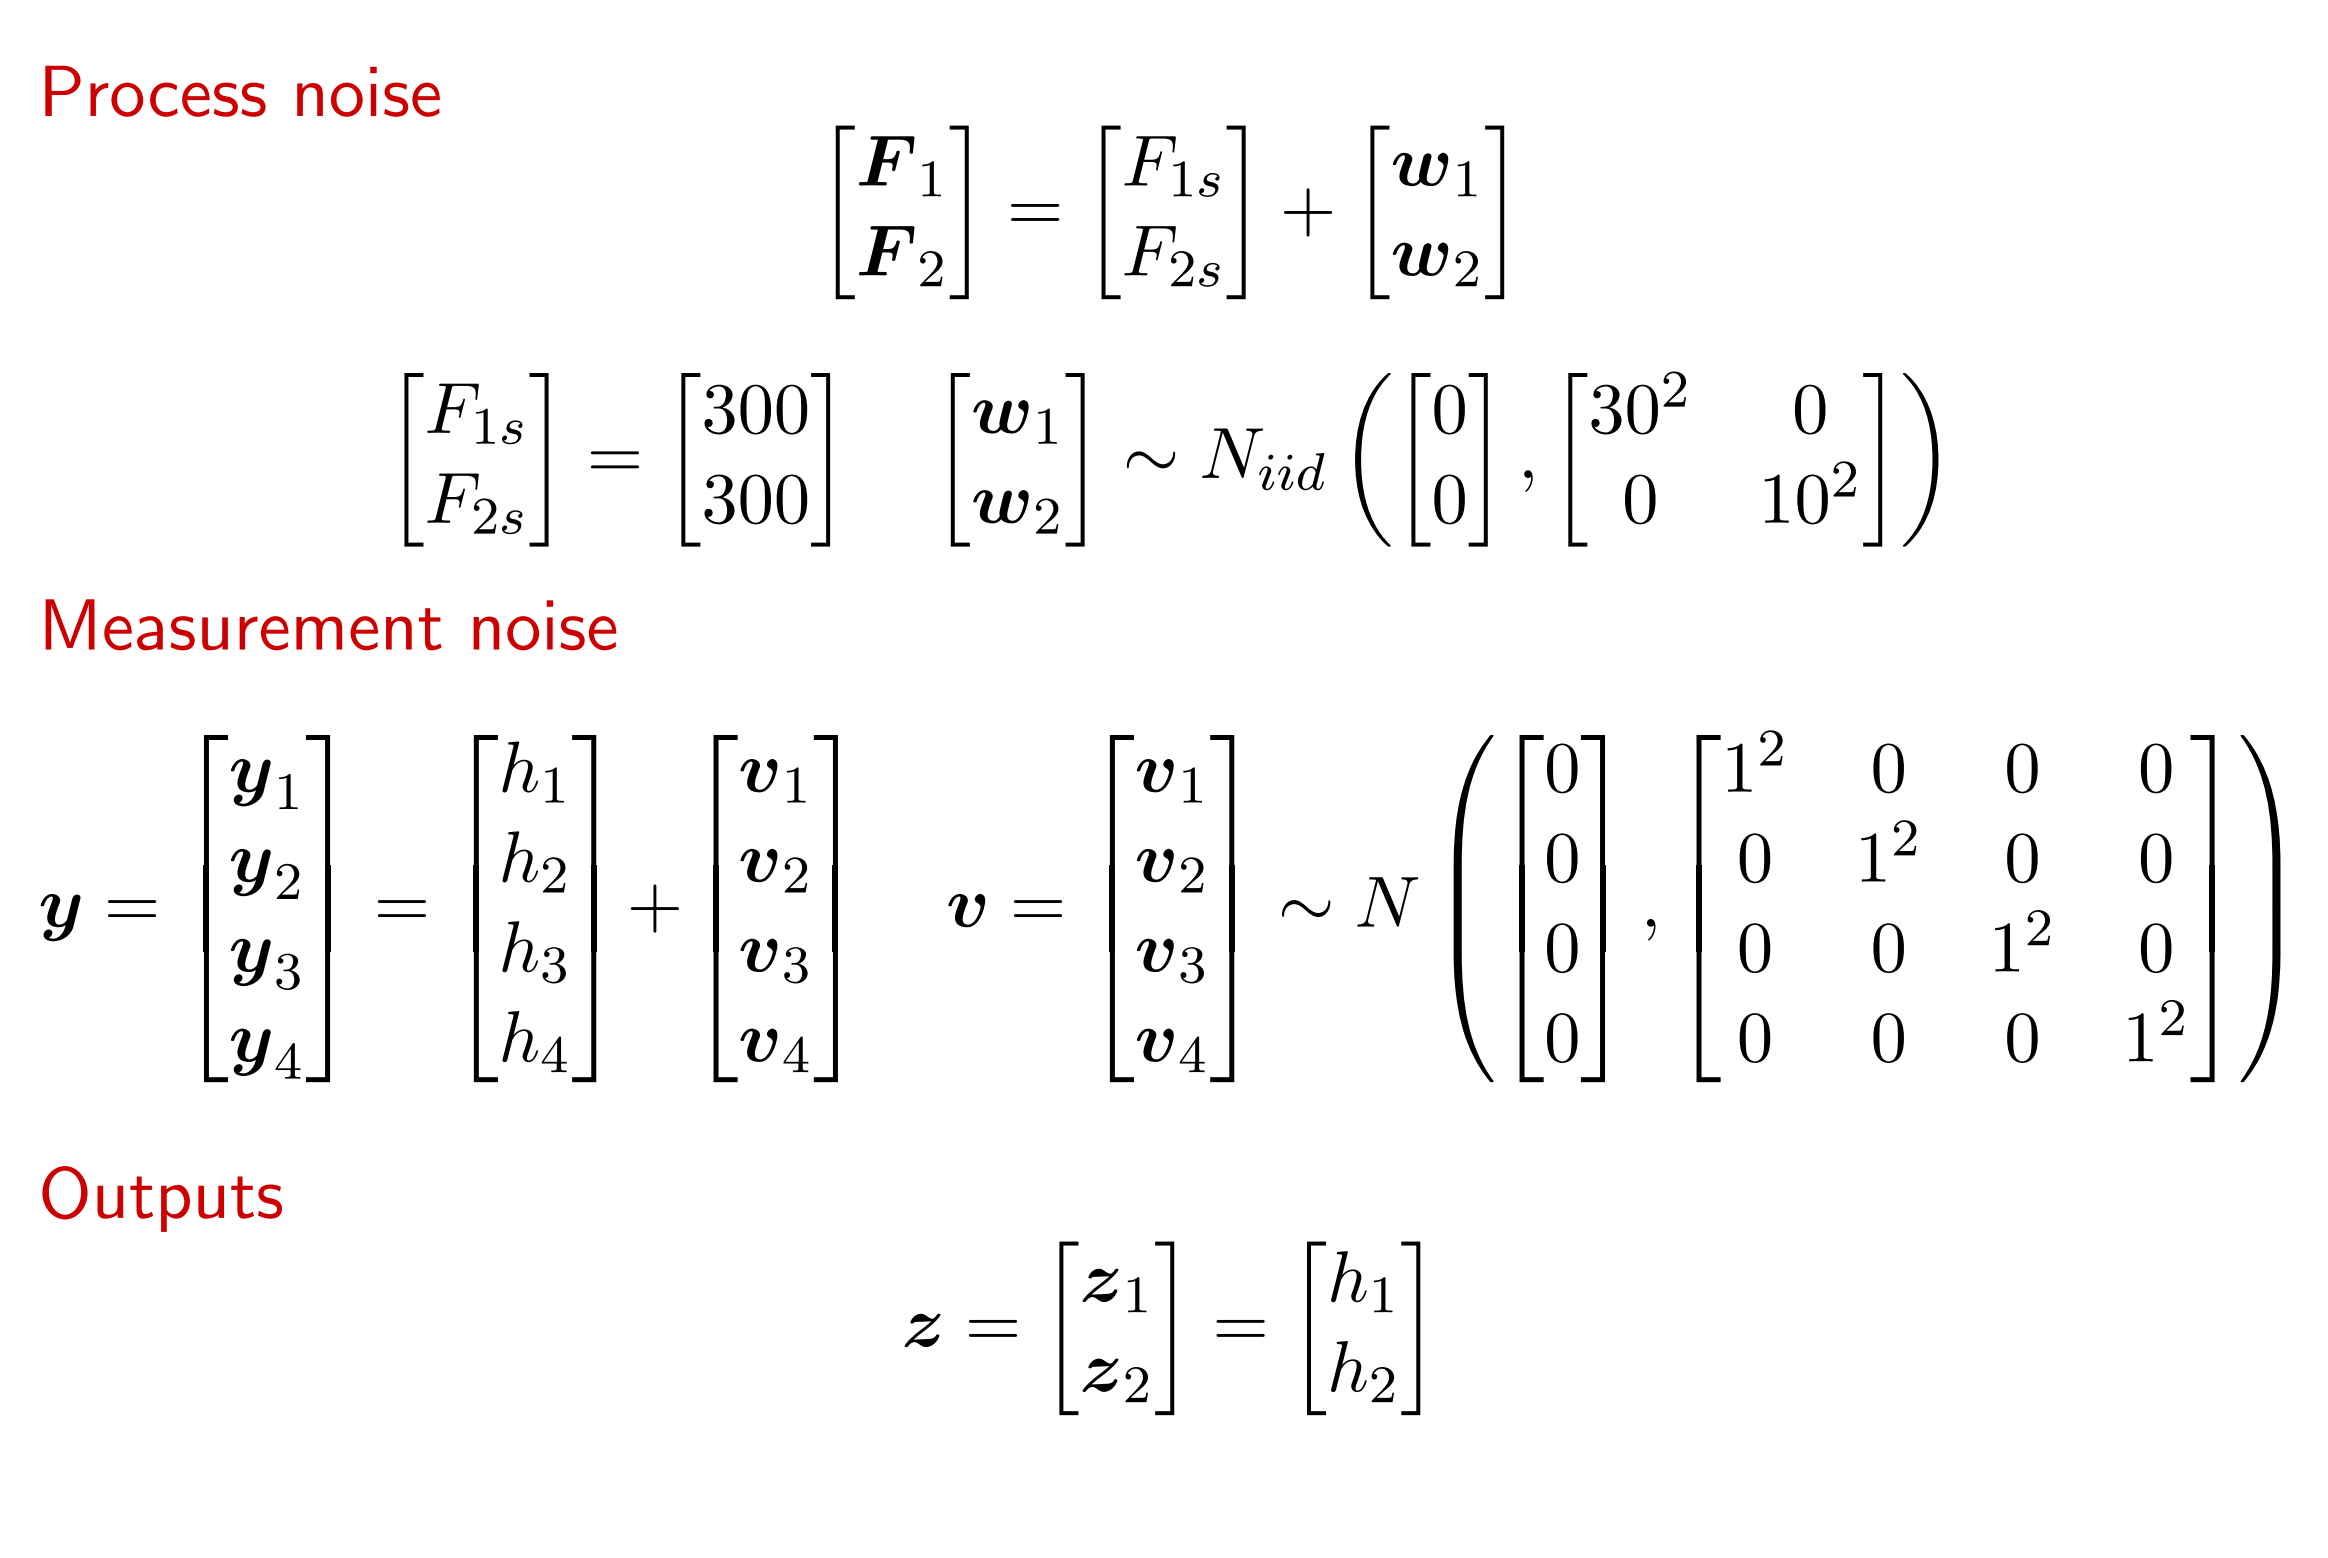

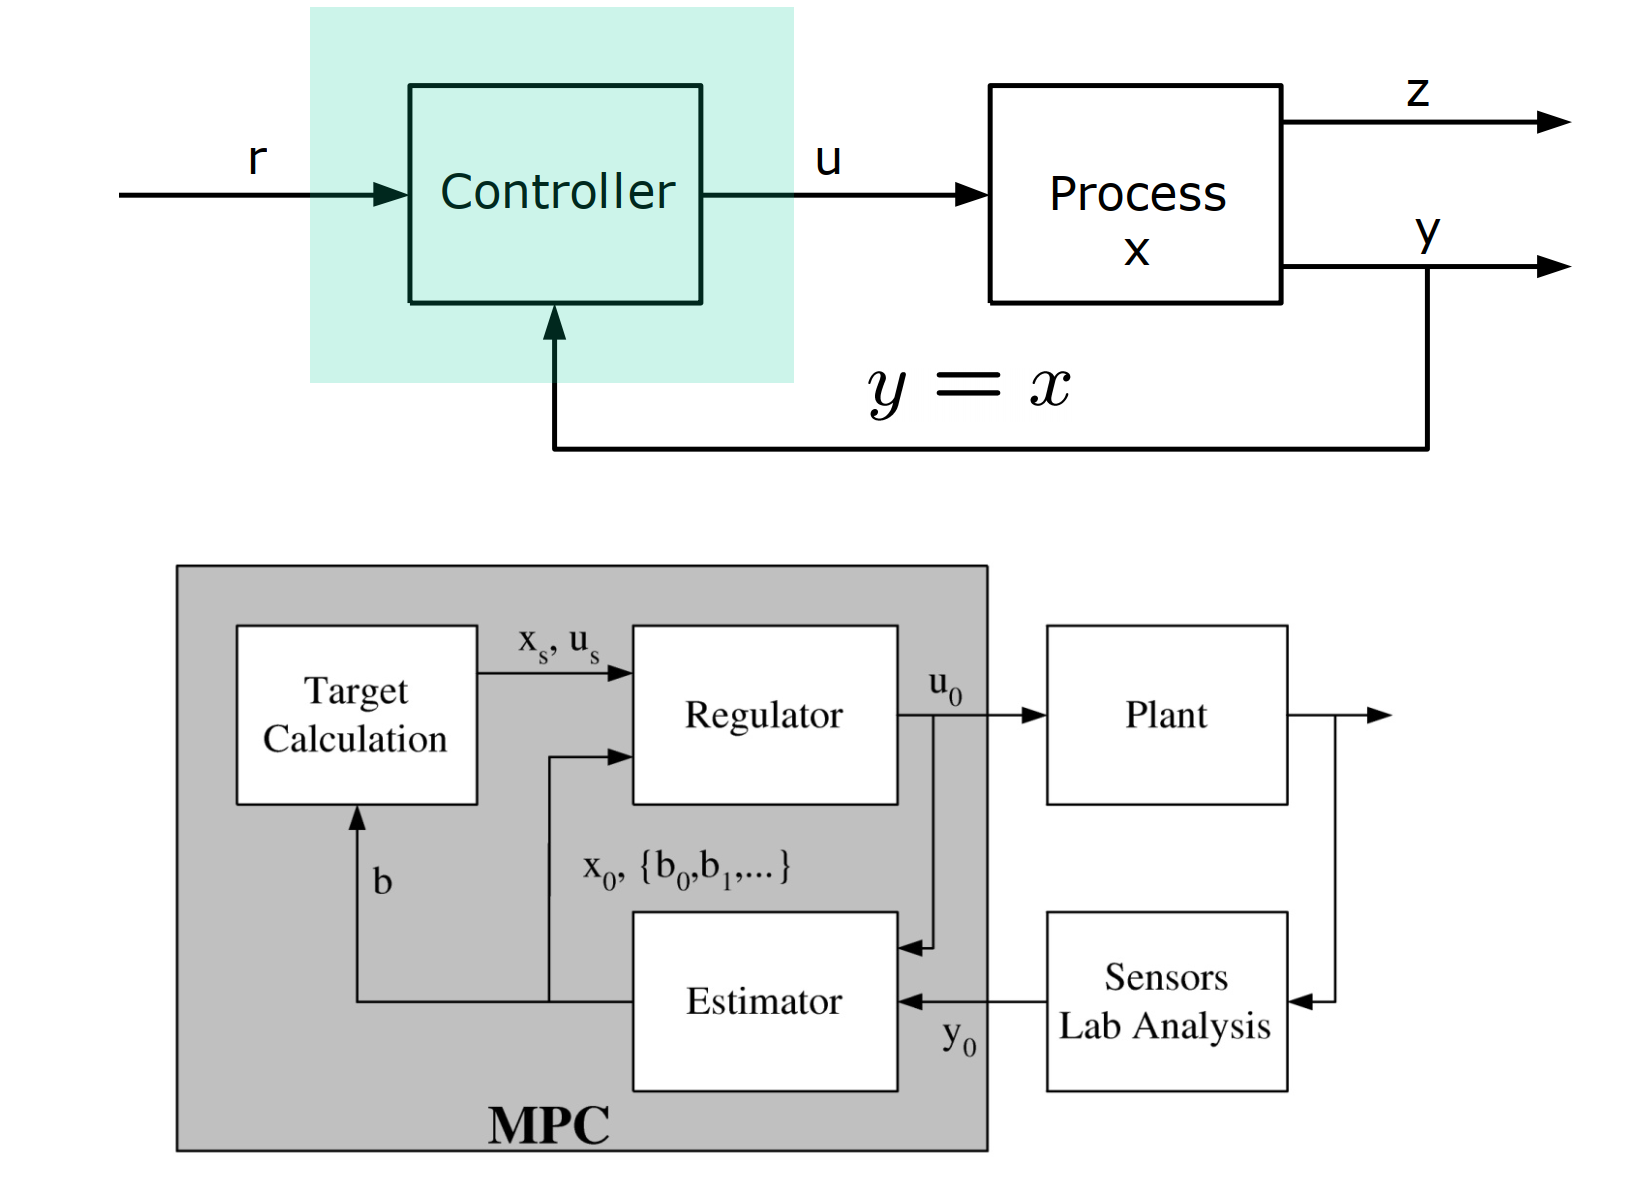

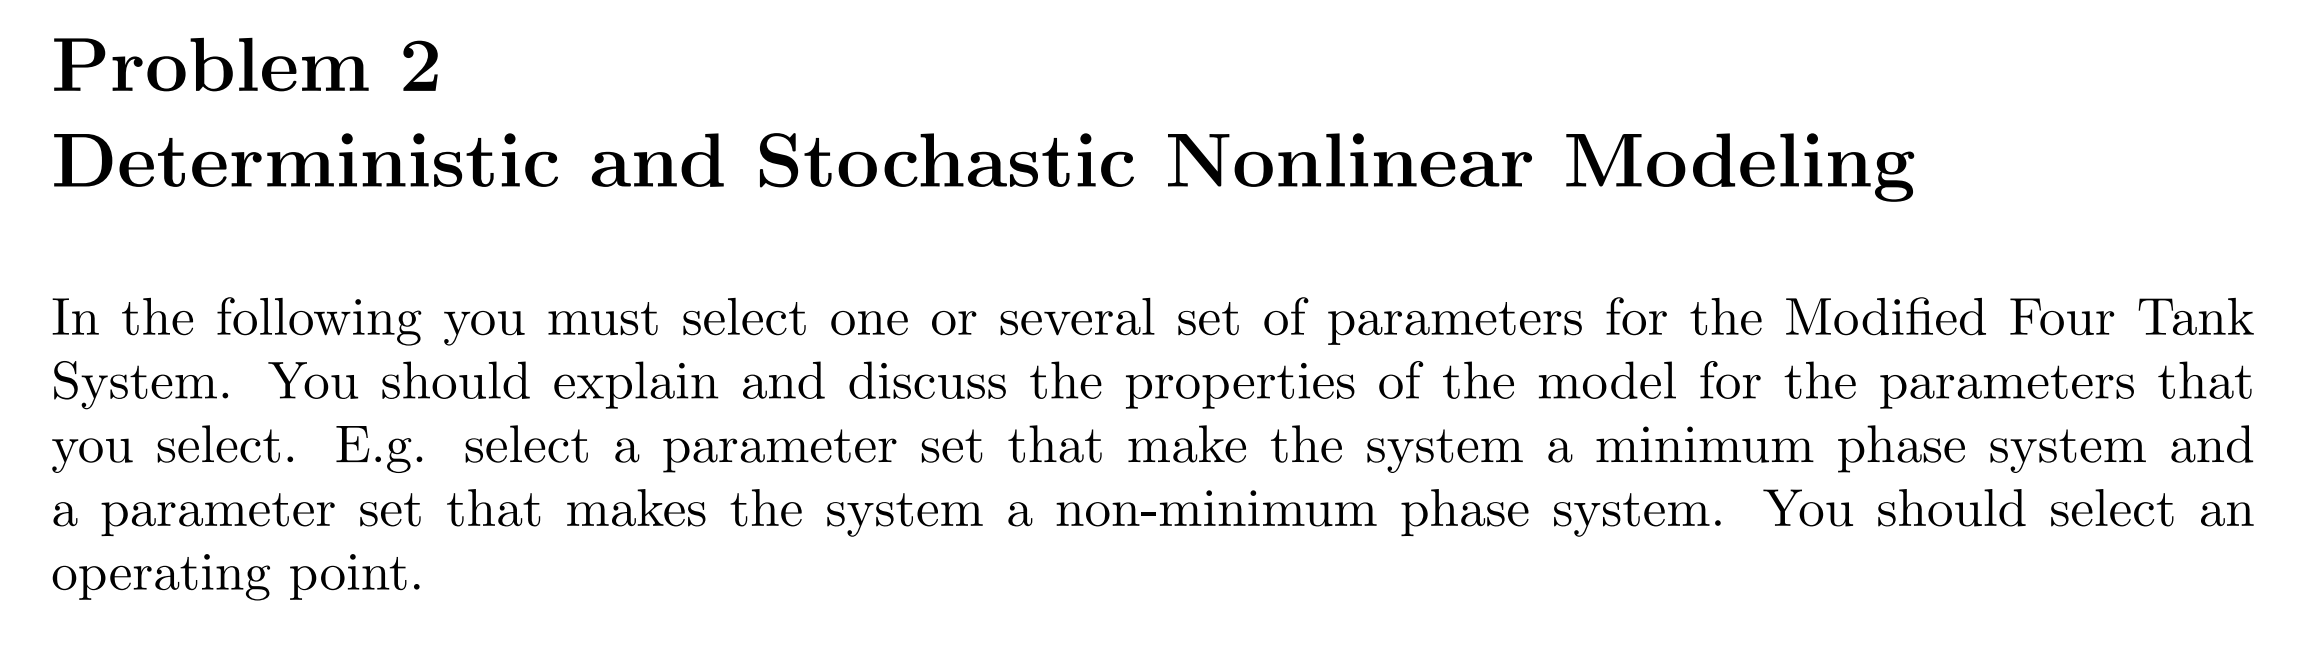

clear all;
% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------

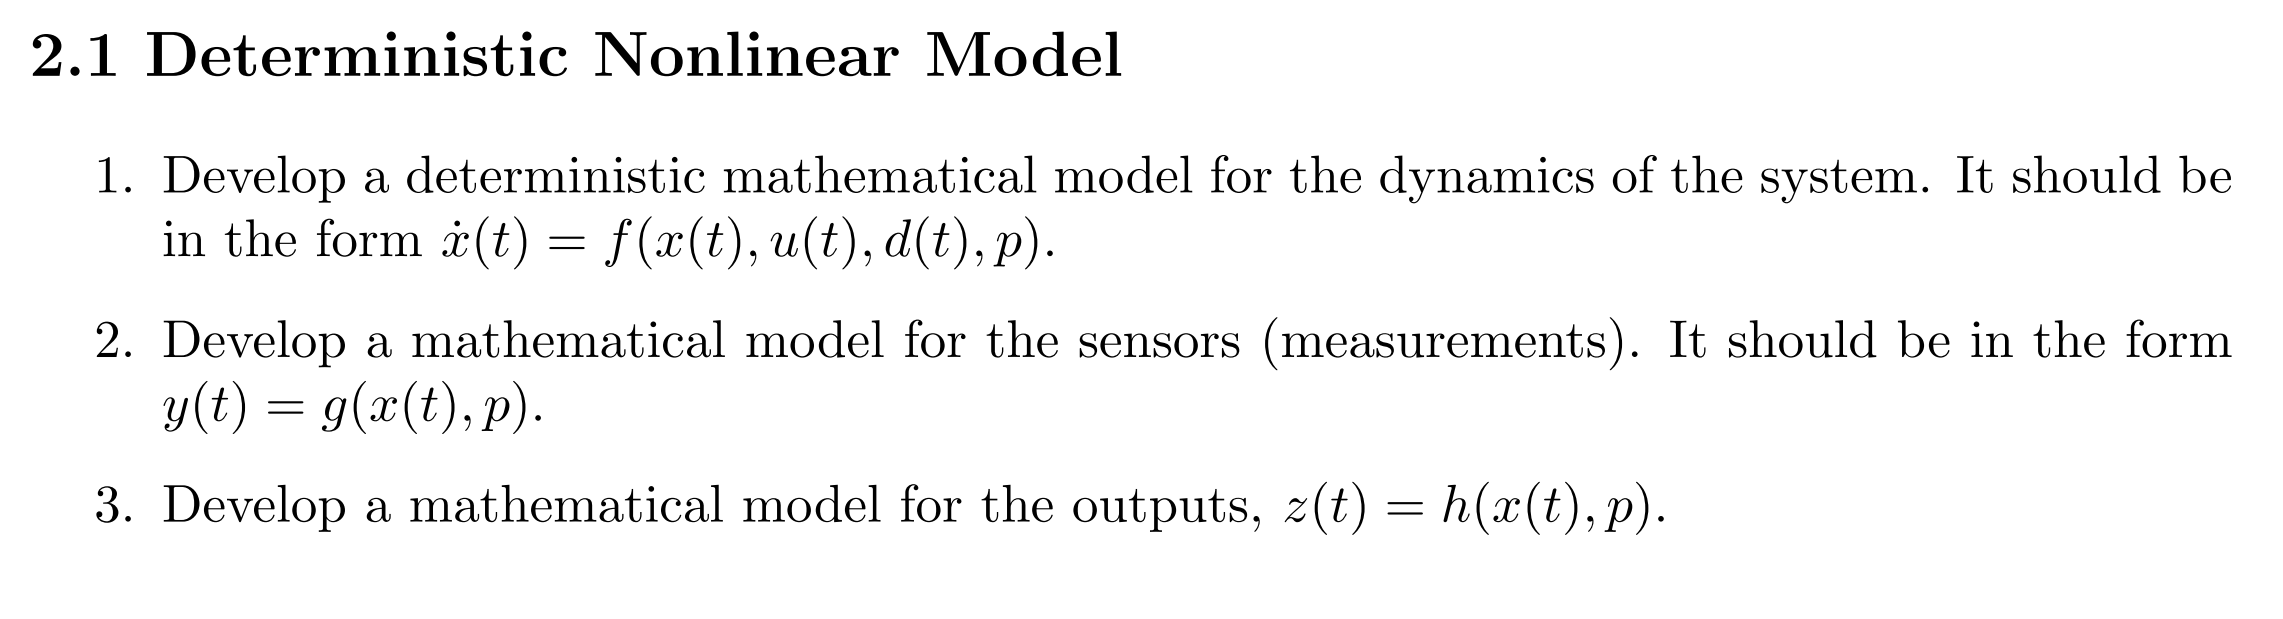

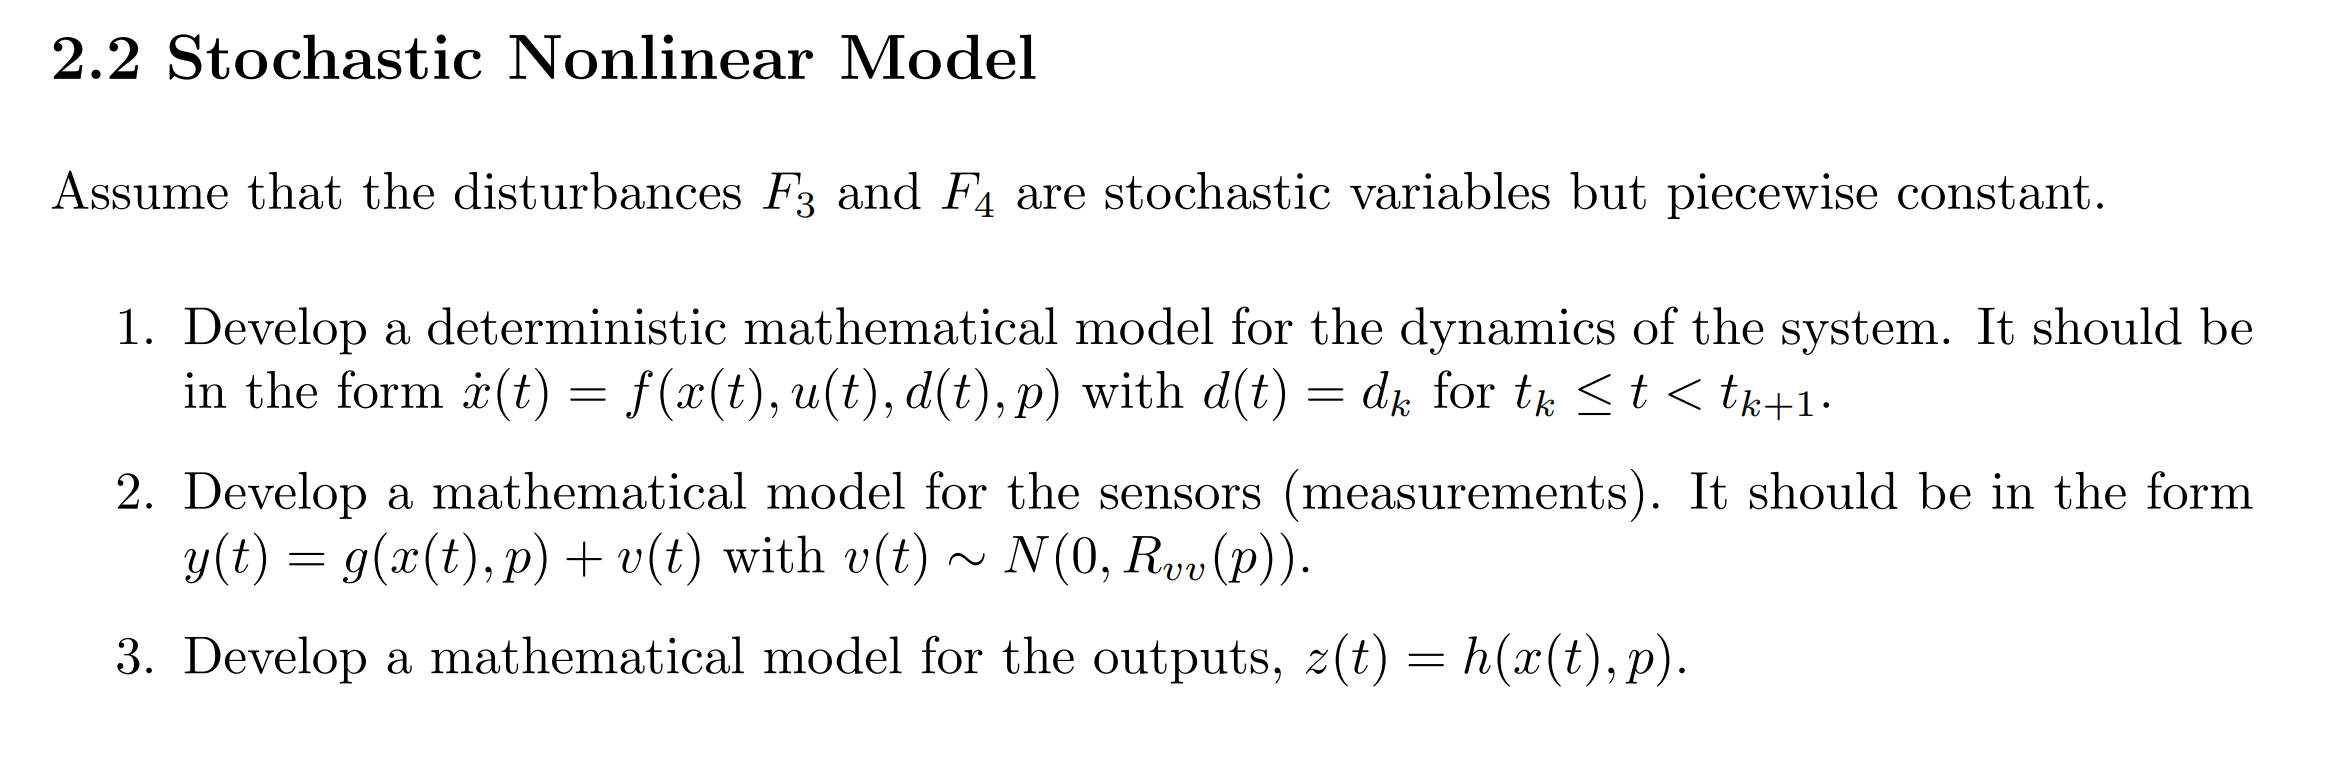

%水箱模型m文件不变，输入的d构造为均值常数的正态分布
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
x0 = [m10; m20; m30; m40];
u = [repmat(F1,1,N); repmat(F2,1,N)];
% Process Noise
Q = [20^2 0;0 40^2];
Lq = chol(Q,'lower');
w = Lq*randn(2,N);
% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);

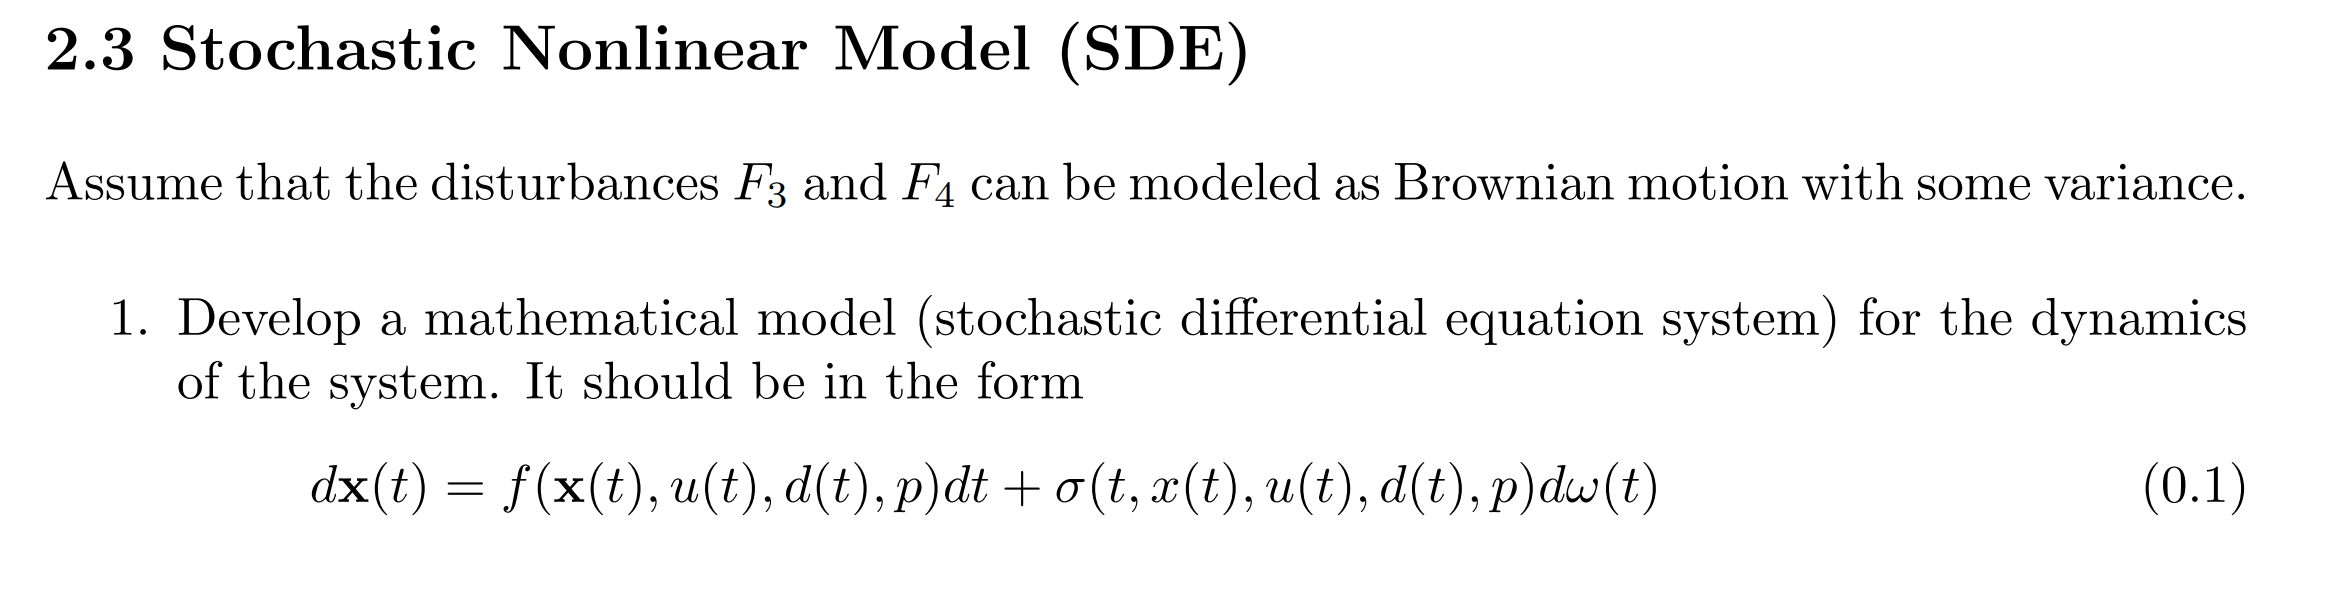

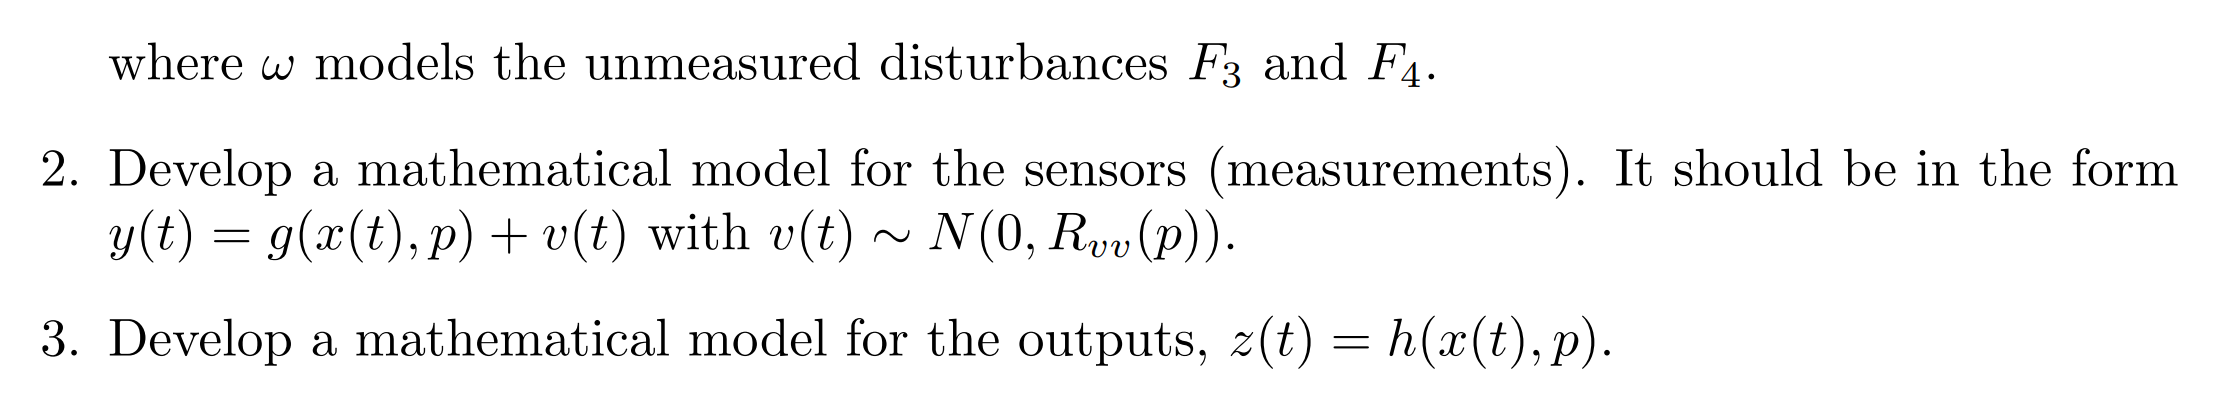

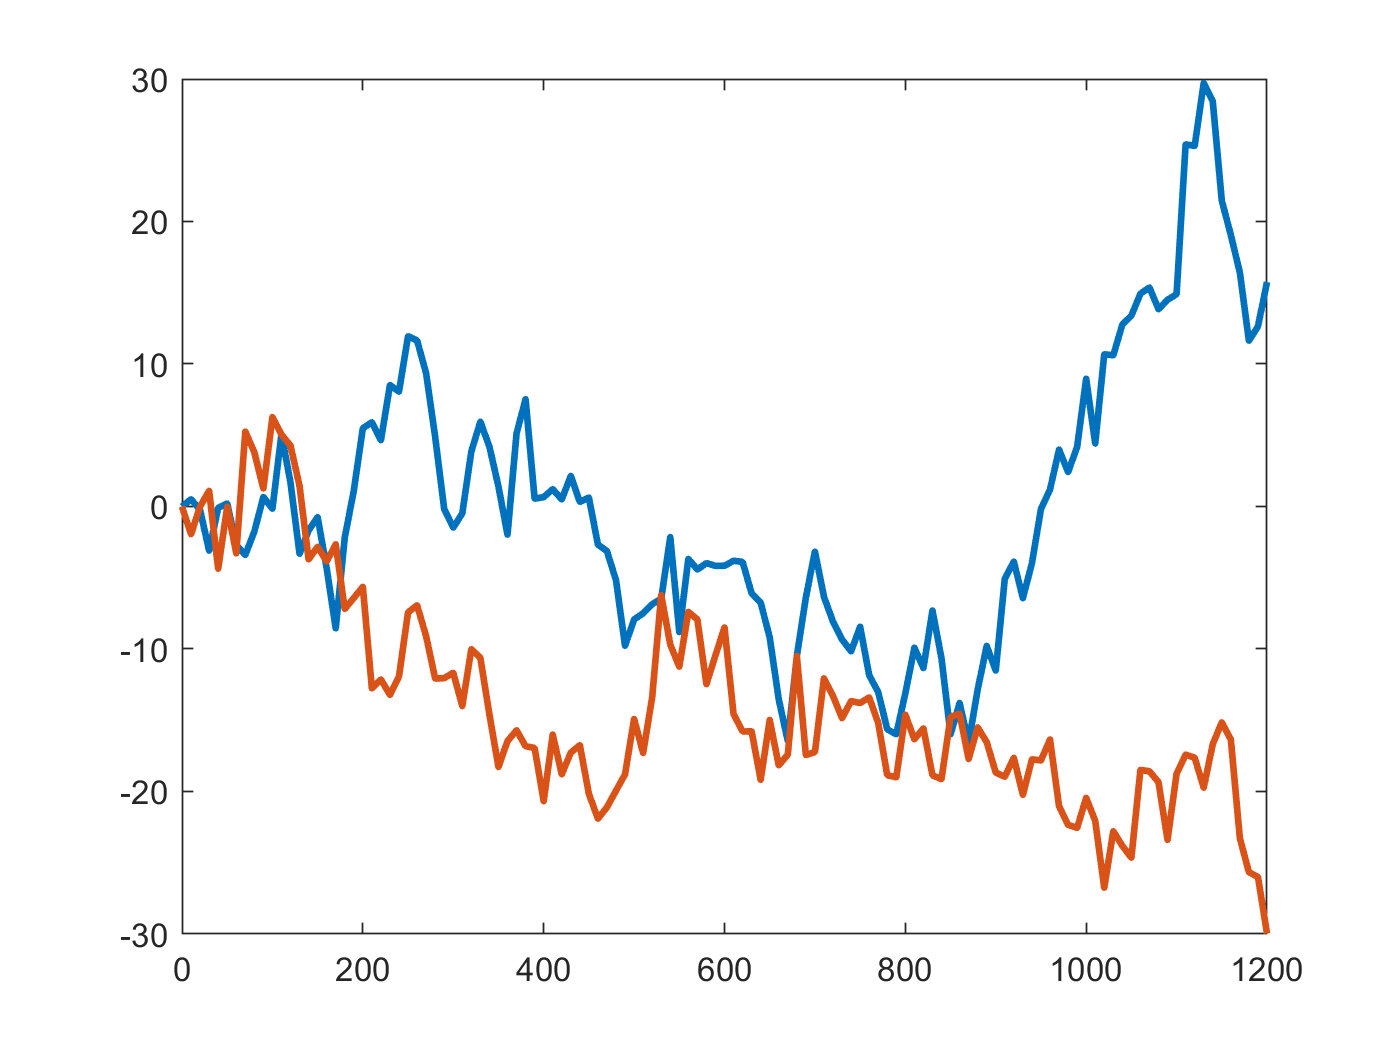

%同样只改变干扰噪音的构造，构造为维纳过程
% Scalar Standard Brownian Motion = Standard Wiener Process
Ns = 2; % Number of realizations
t_final = 20*60; % Final time
Ts=10;
N = t_final/Ts; % Number of time steps
seed = 100; % Seed for reproducibility
[W,Tw,dW] = ScalarStdWienerProcess(t_final,N,Ns,seed);
plot(Tw,W,'linewidth',2)

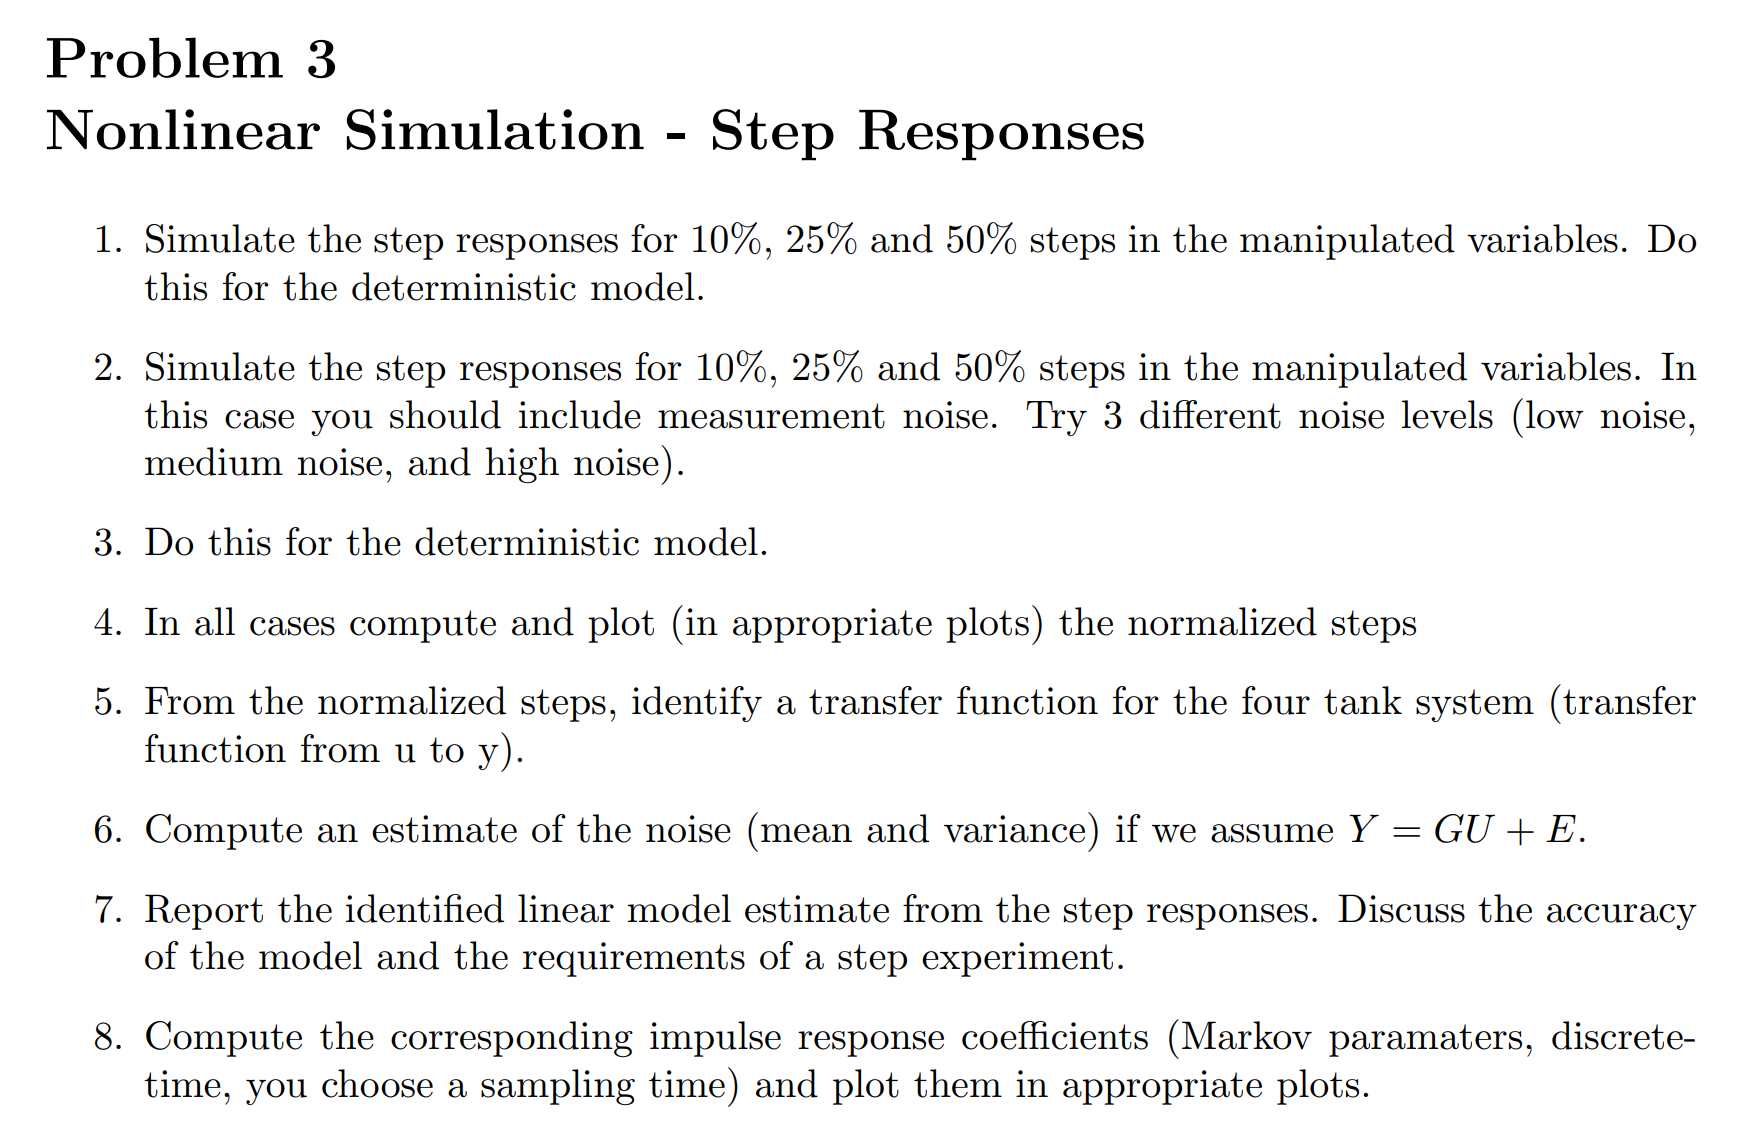

%ex3.1.1 找稳态点，求解非线性方程就可以了，所以使用了fsolve
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F3;F4]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.1068
    3.6822
    2.3787
    2.2157


ys = FourTankSystemSensor(xs,p)

ys =   108.0357
   96.8675
   62.5759
   58.2863


zs = FourTankSystemOutput(xs,p)

zs =   108.0357
   96.8675


%ex3.1 进行非线性系统的仿真，要用离散的仿真 这里我们每十秒一个区间进行仿真
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 4; % [s] Sample Time (4s for the step)
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
%x0 = [m10; m20; m30; m40];
x0=xs;
% Measurement Noise
R = eye(4);
Lr = chol(R,'lower');
v = Lr*randn(4,N);
index_step=100;
%step 0.05
u_50_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_50_F1(1,index_step:end)=F1*(1+0.5);
u_50_F2(2,index_step:end)=F2*(1+0.5);
d = [repmat(F3,1,N); repmat(F4,1,N)];
%step 0.1
u_10_F1 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F2 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10_F1(1,index_step:end)=F1*(1+0.1);
u_10_F2(1,index_step:end)=F2*(1+0.1);
%step 0.25
u_25 = [repmat(F1,1,N); repmat(F2,1,N)];
u_25(1,40:end)=F1*(1+0.25);
%impulse 
u_impluse_F1=[repmat(F1,1,N); repmat(F2,1,N)];
u_impluse_F1(1,200)=F1+1/Ts;
% --------------------------------------------------------------
nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;
for k = 1:N-1
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
%y(:,k) = FourTankSystemSensorNoise(x(:,k),p,v(:,k));
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
u_50_F1(:,k),d(:,k),p);
x(:,k+1) = Xk(end,:)';
T = [T; Tk];
X = [X; Xk];
end
k = N;
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function

[y_row,y_col]=size(y);
s_yu=zeros(y_row,y_col);
for i=1:y_col
    for j=1:4
        s_yu(j,i)=(y(j,i)-ys(j))/(u_10_F1(1,i)-us(1));
    end
end

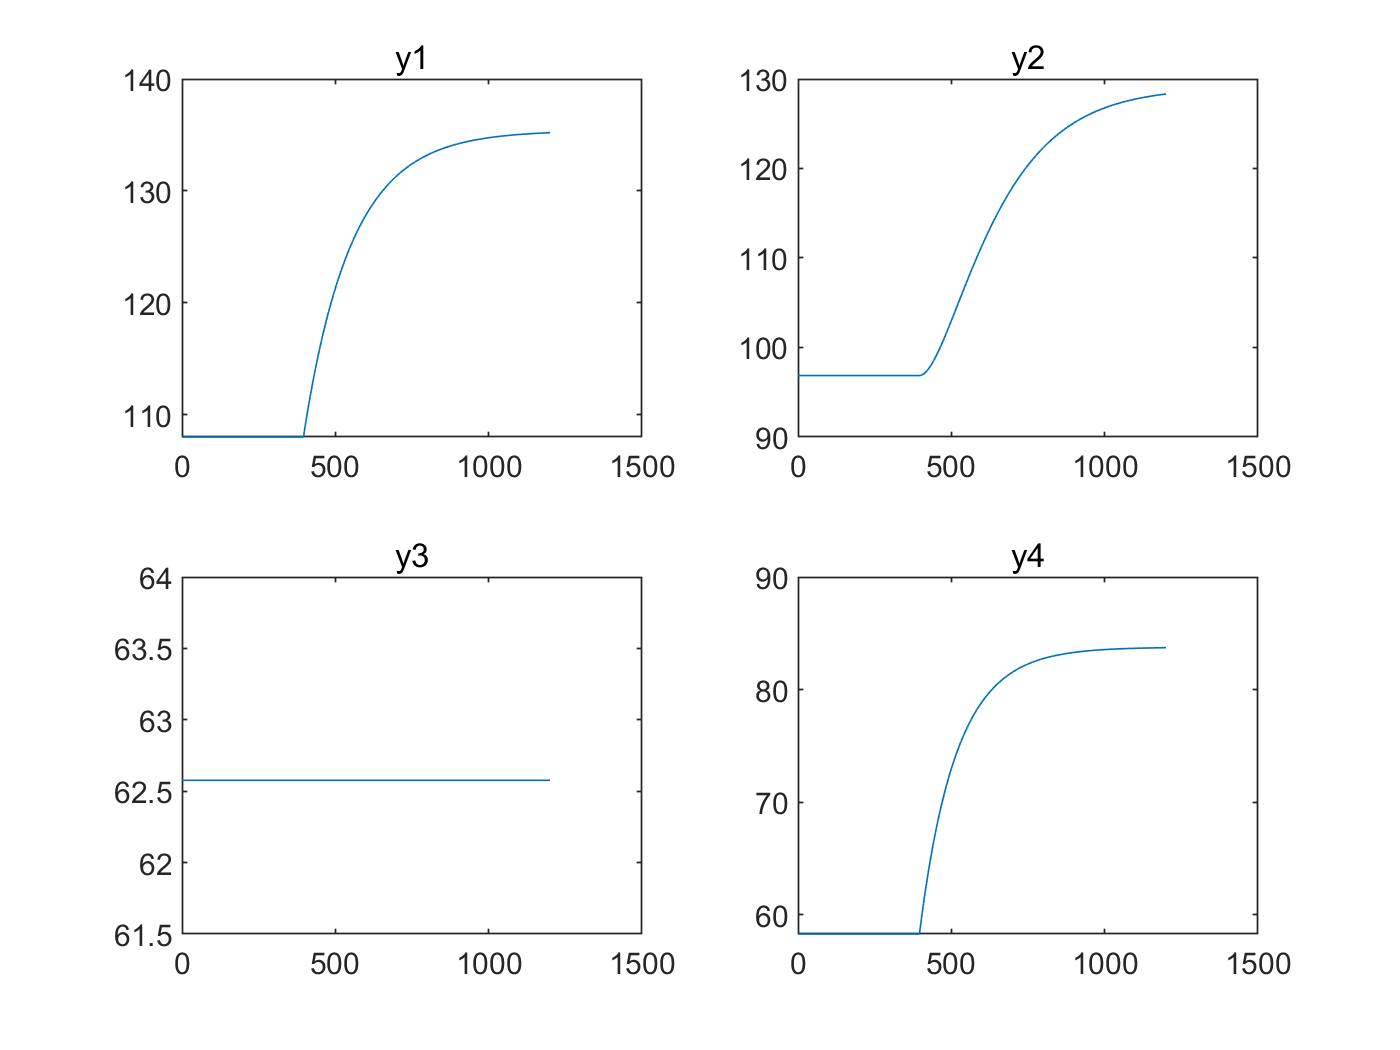

%ex3.1 plot x 
figure
subplot(2,2,1)
plot(t,y(1,:))
title('y1')
subplot(2,2,2)
plot(t,y(2,:))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

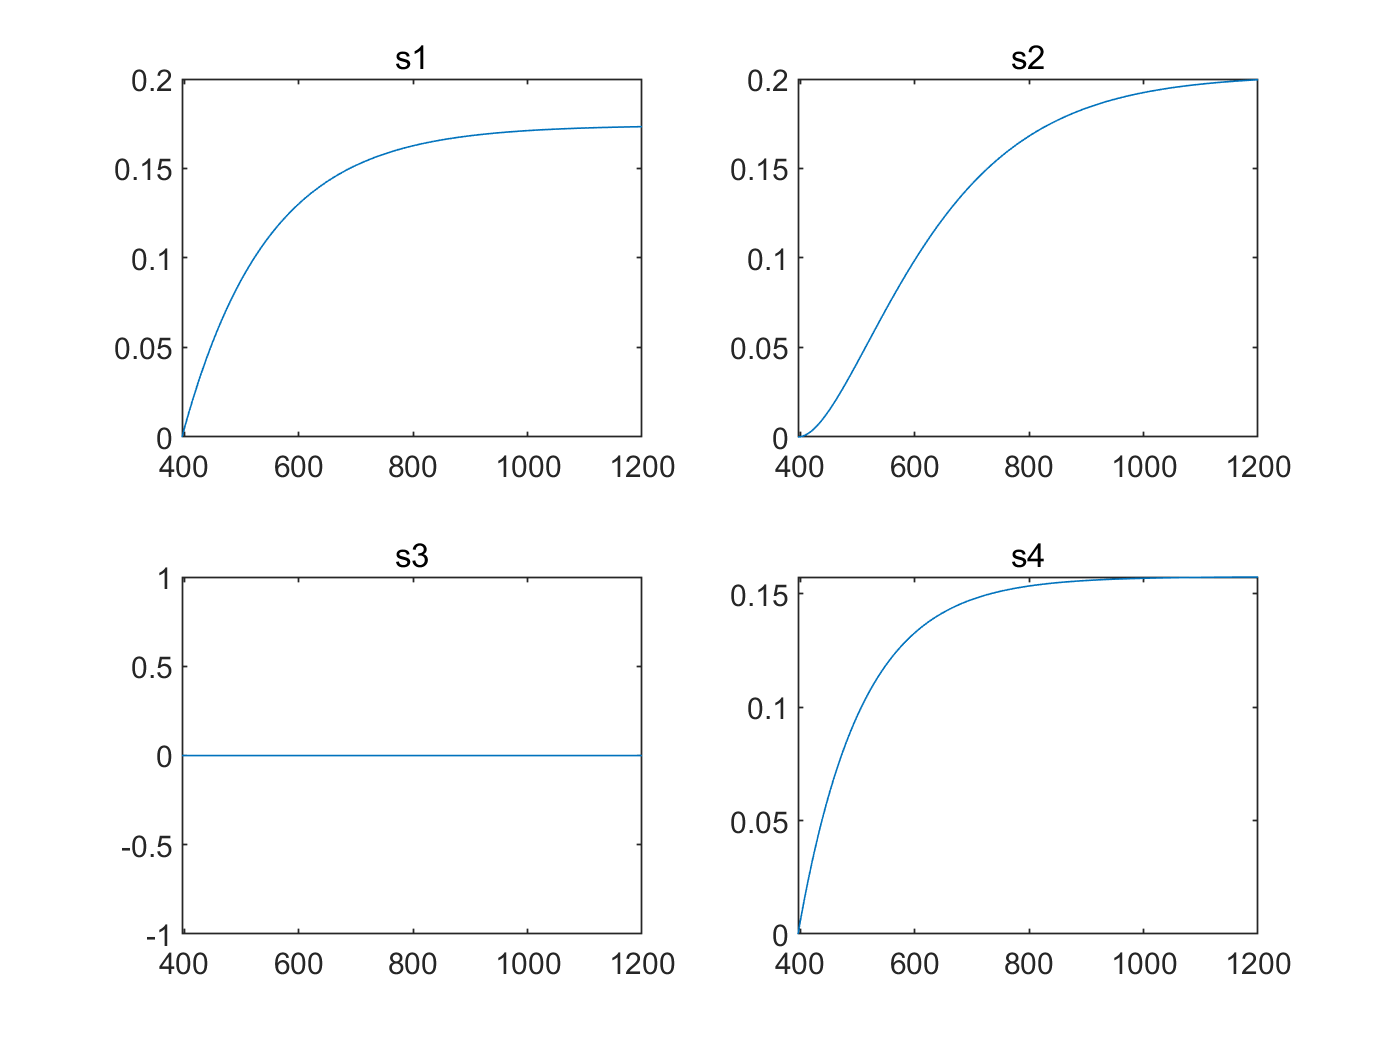

%ex3.1 plot s_yu
figure
subplot(2,2,1)
plot(t,s_yu(1,:))
title('s1')
subplot(2,2,2)
plot(t,s_yu(2,:))
title('s2')
subplot(2,2,3)
plot(t,s_yu(3,:))
title('s3')
subplot(2,2,4)
plot(t,s_yu(4,:))
title('s4')

%系统辨识测试
u1_y_10=u_10_F1(1,:)';
u1_y_10=u1_y_10-us(1)*ones(size(u1_y_10,1),1)

u1_y_10 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


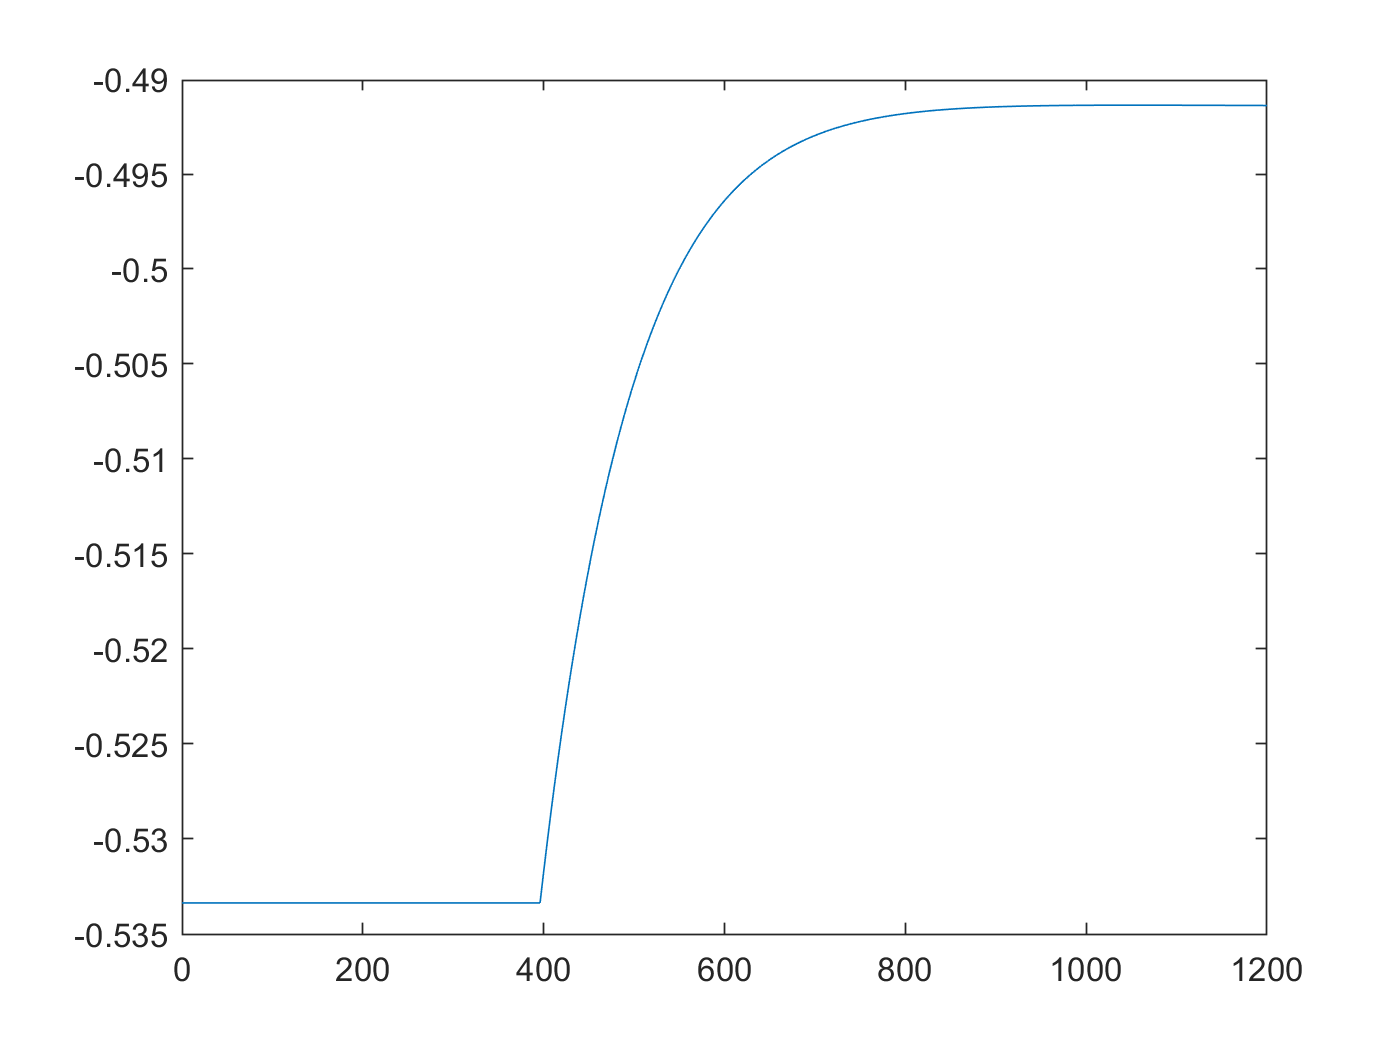

s1_u1_10=s_yu(1,:)';
s2_u1_10=s_yu(2,:)';
s3_u1_10=s_yu(3,:)';
s4_u1_10=s_yu(4,:)';
s1_u1_10(1:index_step-1)=s1_u1_10(index_step);
s2_u1_10(1:index_step-1)=s2_u1_10(index_step);
s3_u1_10(1:index_step-1)=s3_u1_10(index_step);
s4_u1_10(1:index_step-1)=s4_u1_10(index_step);
figure;
plot(t,s1_u1_10)

figure;
y1_iden=lsim(tf4,u1_y_10,t);
y1_iden=y1_iden+s1_u1_10(index_step)*ones(size(y1_iden,1),1)

y1_iden =    -0.5334
   -0.5334
   -0.5334
   -0.5334
   -0.5334
   -0.5334
   -0.5334
   -0.5334
   -0.5334
   -0.5334


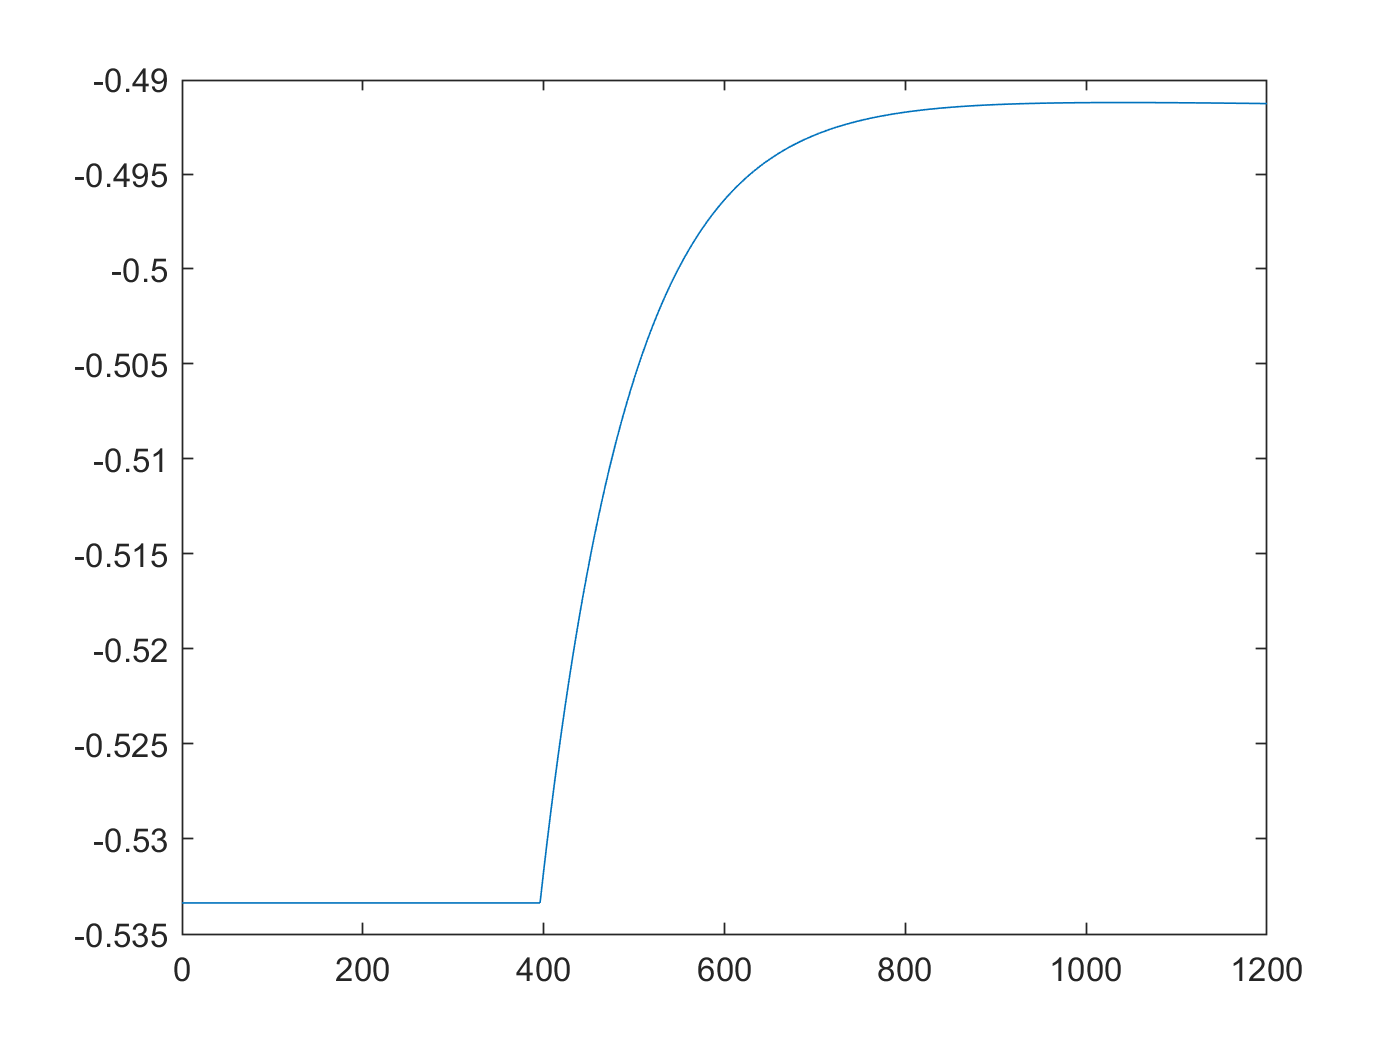

plot(t,y1_iden)

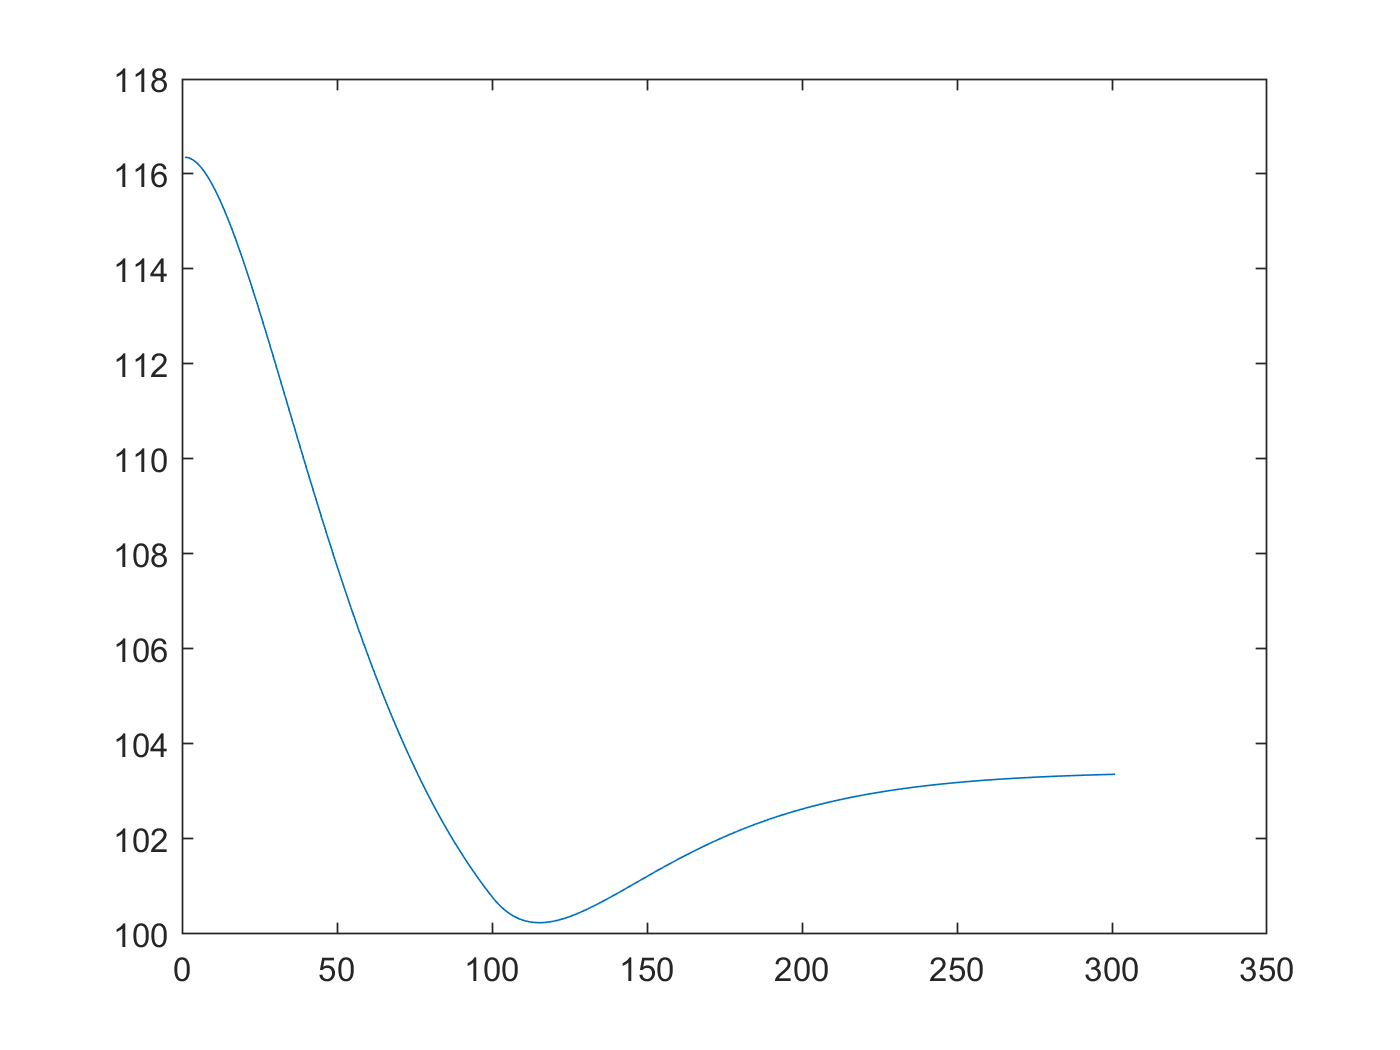

y1_u1_delta=y(2,:)'-y1_iden;
plot(y1_u1_delta)

mean(y1_u1_delta)

ans = 104.2053

var(y1_u1_delta)

ans = 17.4739

mean(v(2,:))

ans = -0.0073

var(v(2,:))

ans = 0.9596

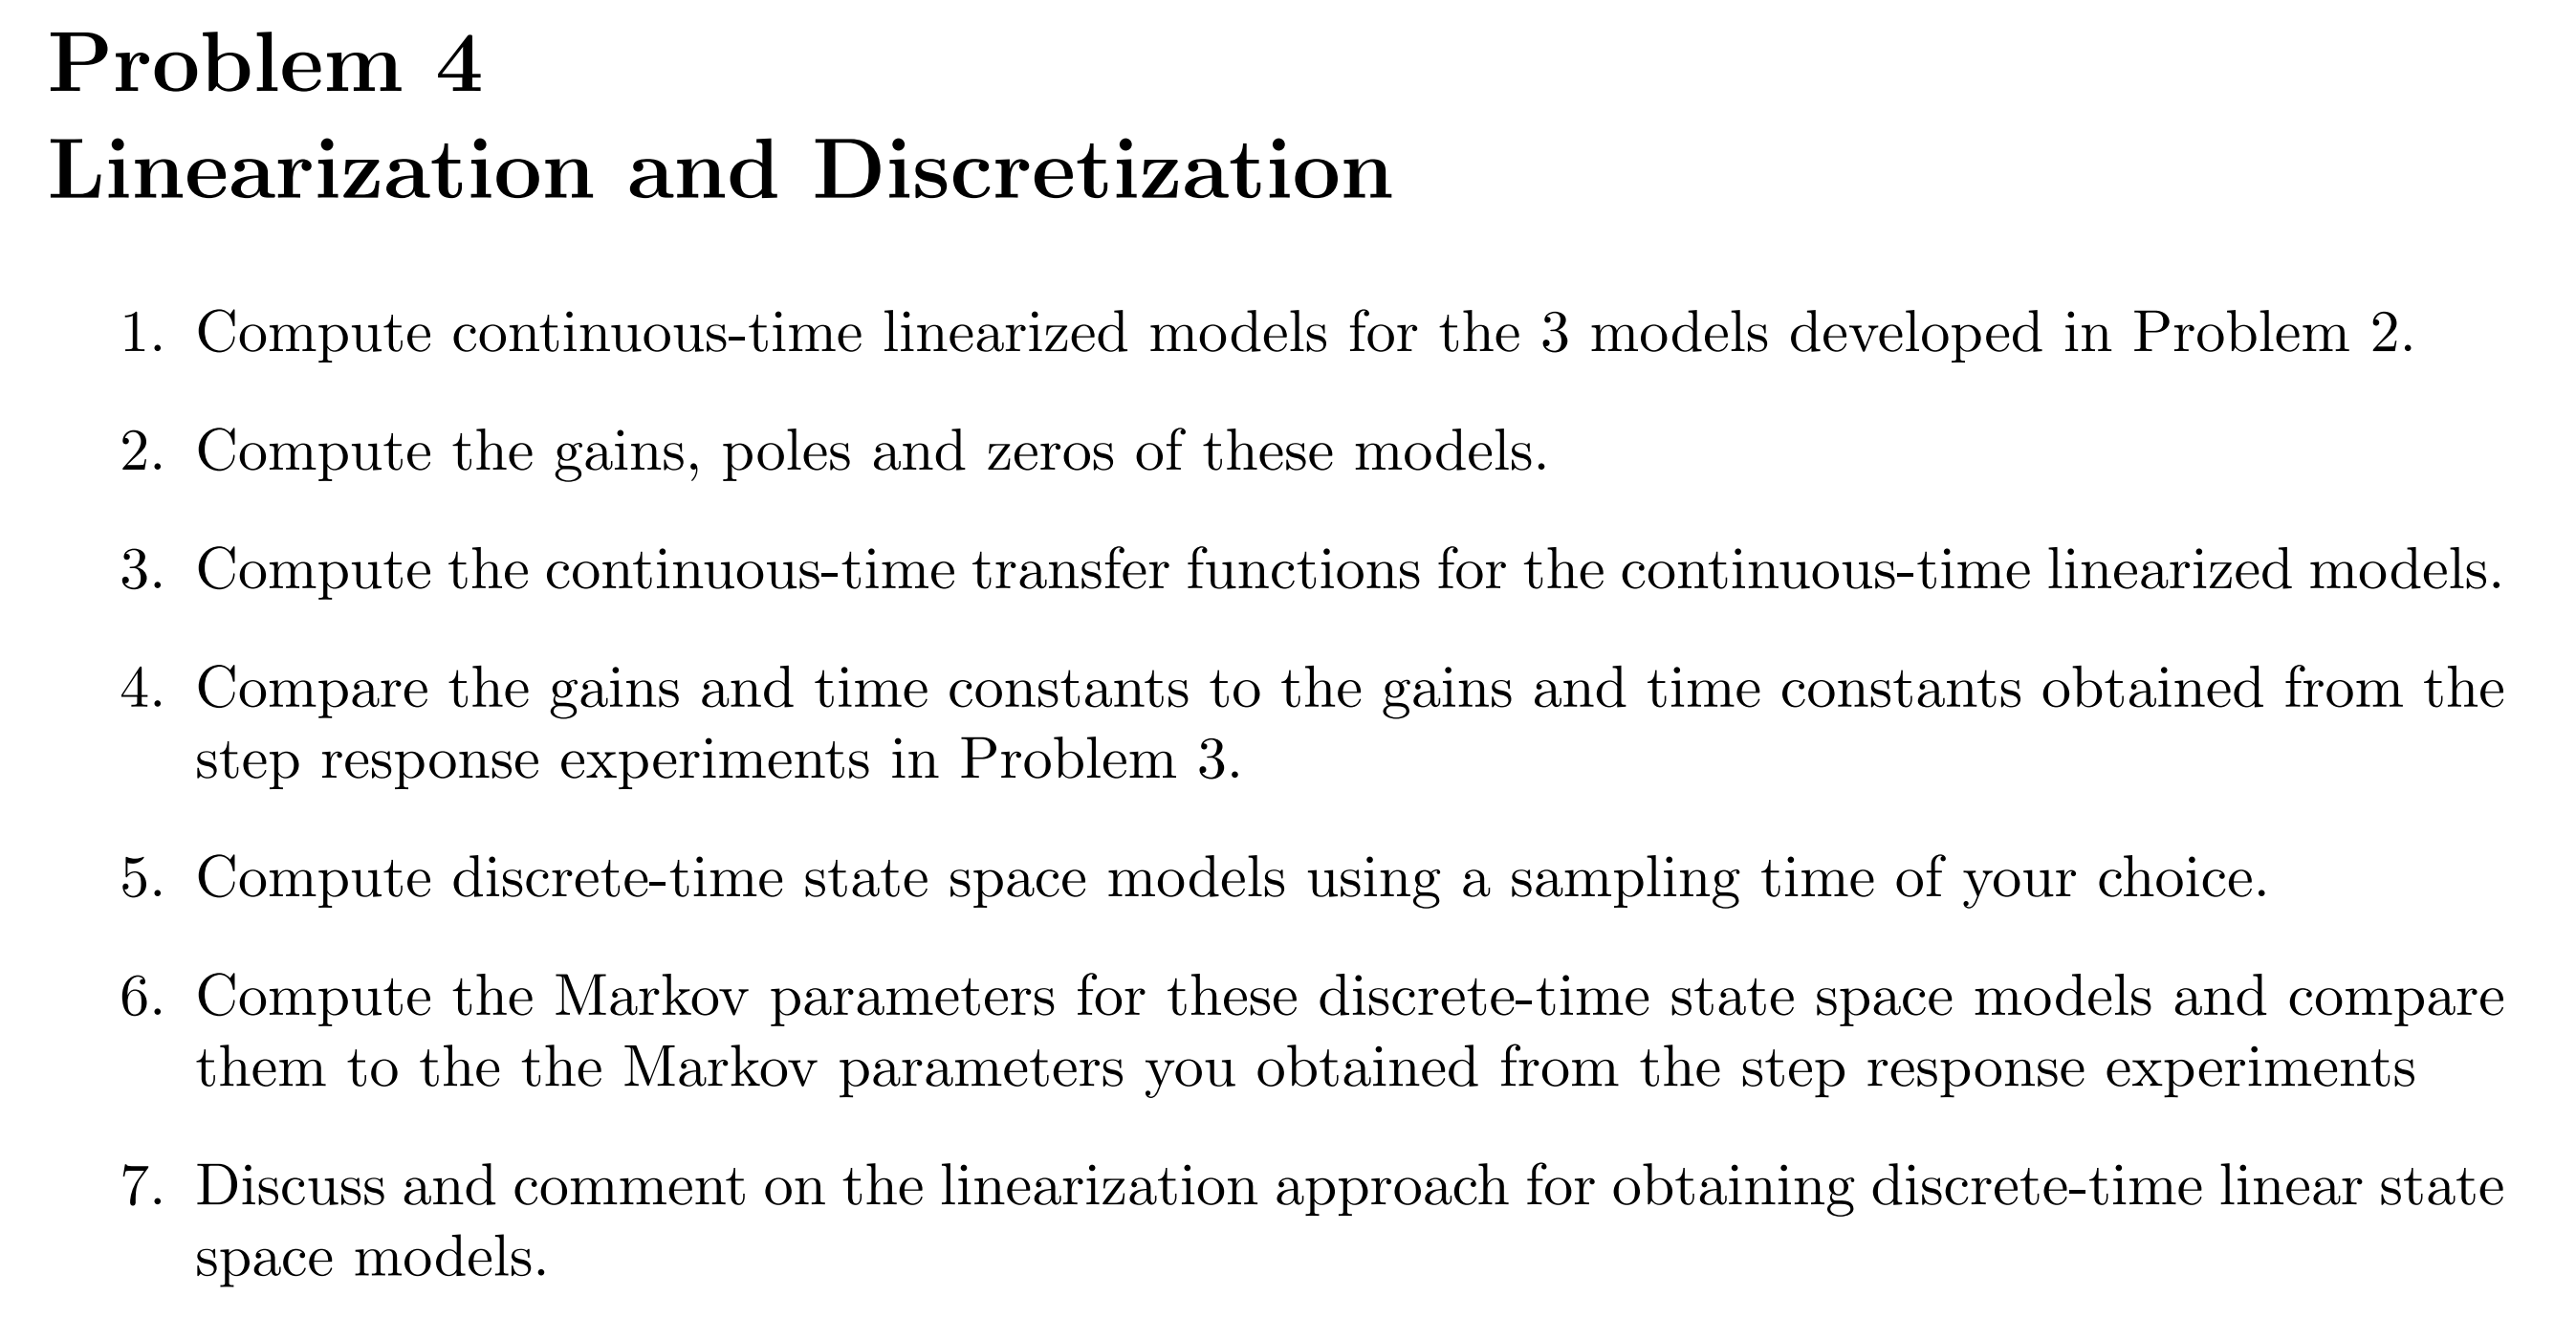


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.8658
    4.4027
    2.9641
    2.7817


ys =   128.0031
  115.8196
   77.9745
   73.1773


zs =   128.0031
  115.8196



%ex3.4.1 对非线性系统进行线性化，需要使用雅可比矩阵求导
syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0069         0    0.0090         0
         0   -0.0073         0    0.0094
         0         0   -0.0090         0
         0         0         0   -0.0094


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Czss=Css(1:2,:)

Czss =     0.0026         0         0         0
         0    0.0026         0         0


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0


Dzss=Dss(1:2,:)

Dzss =      0     0
     0     0


%ex3.5 线性系统的离散化
Ts = 4; 
[Ad,Bd]=c2dzoh(Ass,Bss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd =     1.7755    0.0425
    0.0403    1.5770
         0    2.3571
    2.1593         0


[Ad,Bd_d]=c2dzoh(Ass,Bdss,Ts)

Ad =     0.9729         0    0.0350         0
         0    0.9714         0    0.0362
         0         0    0.9645         0
         0         0         0    0.9632


Bd_d =     0.0708         0
         0    0.0733
    3.9286         0
         0    3.9260


sys_ss=ss(Ass,Bdss,Css,Dss);
sys_ss_d=ss(Ad,Bd,Css,Dss,Ts);
figure;
step(sys_ss)
figure;
step(sys_ss_d)

%无约束线性MPC算法设计，考虑前馈（扰动）和输入的变化率
num_x=4;
num_u=2;
num_d=2;
num_y=4;
num_z=2;
U=[1;1];
num_u_delta_cons=N*num_u;
N=5;
Phi=zeros(N*num_z,num_x);%[CA]*x0 ->>> z #####[num_z*N,num_x]
Gam=zeros(N*num_z,N*num_u);%[H]*Uk ->>> z
Gam_d=zeros(N*num_z,N*num_d);%[Hd]*Dk ->>> z

%预测值与参考值误差的权重矩阵Qz,海森矩阵Hr,一阶梯度Mr
Qz=diag(ones(N*num_z,1)) ;
%input rate的权重矩阵S,海森矩阵Hs,一阶梯度Mu_delta
Sz=diag(ones(num_u,1));
Hs=zeros(N*num_u,N*num_u);
Mu_delta=zeros(N*num_u,num_u);
Mu_delta(1:num_u,:)=-Sz;
U0=zeros(N*num_u,1);
Iu=diag(ones(num_u,1));
Au_delta_cons=zeros(num_u_delta_cons,N*num_u);

for i=1:N
    %fill the Phi
    Phi((i-1)*num_z+1:i*num_z,:)=Czss*Ad^i;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Gam
    Gam_i=zeros(num_z,N*num_u);%[num_x * num_u*N]
    for j=1:i
        Gam_i(:,(j-1)*num_u+1:j*num_u)=Czss*(Ad^(i-j))*Bd;%[Hn,Hn-1,Hn-2]
    end
    Gam((i-1)*num_z+1:i*num_z,:)=Gam_i;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Gam_d
    Gam_di=zeros(num_z,N*num_d);%[num_x * num_u*N]
    for j=1:i
        Gam_di(:,(j-1)*num_d+1:j*num_d)=Czss*(Ad^(i-j))*Bd_d;%[Hn,Hn-1,Hn-2]
    end
    Gam_d((i-1)*num_z+1:i*num_z,:)=Gam_di;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %fill the Hs
    if i==1
        Hs(1:num_u,1:2*num_u)=[2*Sz,-Sz];
    elseif i==N
        Hs(end-num_u+1:end,end-2*num_u+1:end)=[-Sz,Sz];
    else
        Hs((i-1)*num_u+1:(i)*num_u,(i-2)*num_u+1:(i+1)*num_u)=[-Sz,2*Sz,-Sz];
    end
    %fill the U0
    U0((i-1)*num_u+1:i*num_u,:)=U;
    %fill the Au_delta_cons
    if i==1
        Au_delta_cons(1:num_u,1:num_u)=Iu;
    else
        Au_delta_cons((i-1)*num_u+1:(i)*num_u,(i-2)*num_u+1:i*num_u)=[-Iu,Iu];
    end
end
%初始状态值的一阶梯度Mx0, 干扰项的一阶梯度Md
%预测值与参考值误差的一阶梯度Mr
%input rate的一阶梯度Mu_delta
%g=Mx0*x0+Mr*ref+Ms
Mx0=Gam'*Qz*Phi;
Md=Gam'*Qz*Gam_d;
Mr=-Gam'*Qz;
Hr=Gam'*Qz*Gam;
Hu=Hr+Hs;
Lx0=-Hu\Mx0;
Lr=-Hu\Mr;
Lu_delta=-Hu\Mu_delta;
Ld=-Hu\Md;
Kx0=Lx0(1:num_u,:)

Kx0 = 	1.0e+-3 *

   -0.1606   -0.0127   -0.0206   -0.0019
   -0.0135   -0.1417   -0.0019   -0.0188


Kr=Lr(1:num_u,:)

Kr =     0.0047    0.0001    0.0092    0.0004    0.0136    0.0009    0.0179    0.0016    0.0221    0.0024
    0.0001    0.0041    0.0004    0.0082    0.0010    0.0121    0.0017    0.0159    0.0026    0.0196


Ku_delta=Lu_delta(1:num_u,:)

Ku_delta =     0.9989   -0.0002
   -0.0002    0.9991


Kd=Ld(1:num_u,:)

Kd = 	1.0e+-4 *

   -0.7185   -0.0670   -0.5109   -0.0499   -0.3163   -0.0325   -0.1532   -0.0166   -0.0411   -0.0047
   -0.0688   -0.6566   -0.0511   -0.4673   -0.0333   -0.2896   -0.0170   -0.1404   -0.0048   -0.0377


%u_new=Kx0*Y+Kr*R+Ku_delta*U+Kd*D;

chol(Hs)

%闭环测试线性MPC，对线性离散系统
t0 = 0.0; % [s] Initial time
t_final = 2000; % [s] Final time
Ts = 4; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
N_pre=10;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x0=zeros(4,1);
x(:,1) = x0;
xk=x0;
rk=200*ones(N_pre*num_z,1);%z1,z2 ref
dk=ones(N_pre*num_d,1);%d1,d2 ref
uk=zeros(num_u,1);%d1,d2 ref
for k = 1:N-1
yk=Css*xk; % Sensor function
zk=Czss*xk; % Output function
%uk=MPCcompute_linear(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_analytical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
uk=MPCcompute_linear_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
xk=Ad*xk+Bd*uk+Bd_d*dk(1:num_d);
x(:,k+1)=xk;
y(:,k+1)=yk;
z(:,k+1)=zk;
u(:,k+1)=uk;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

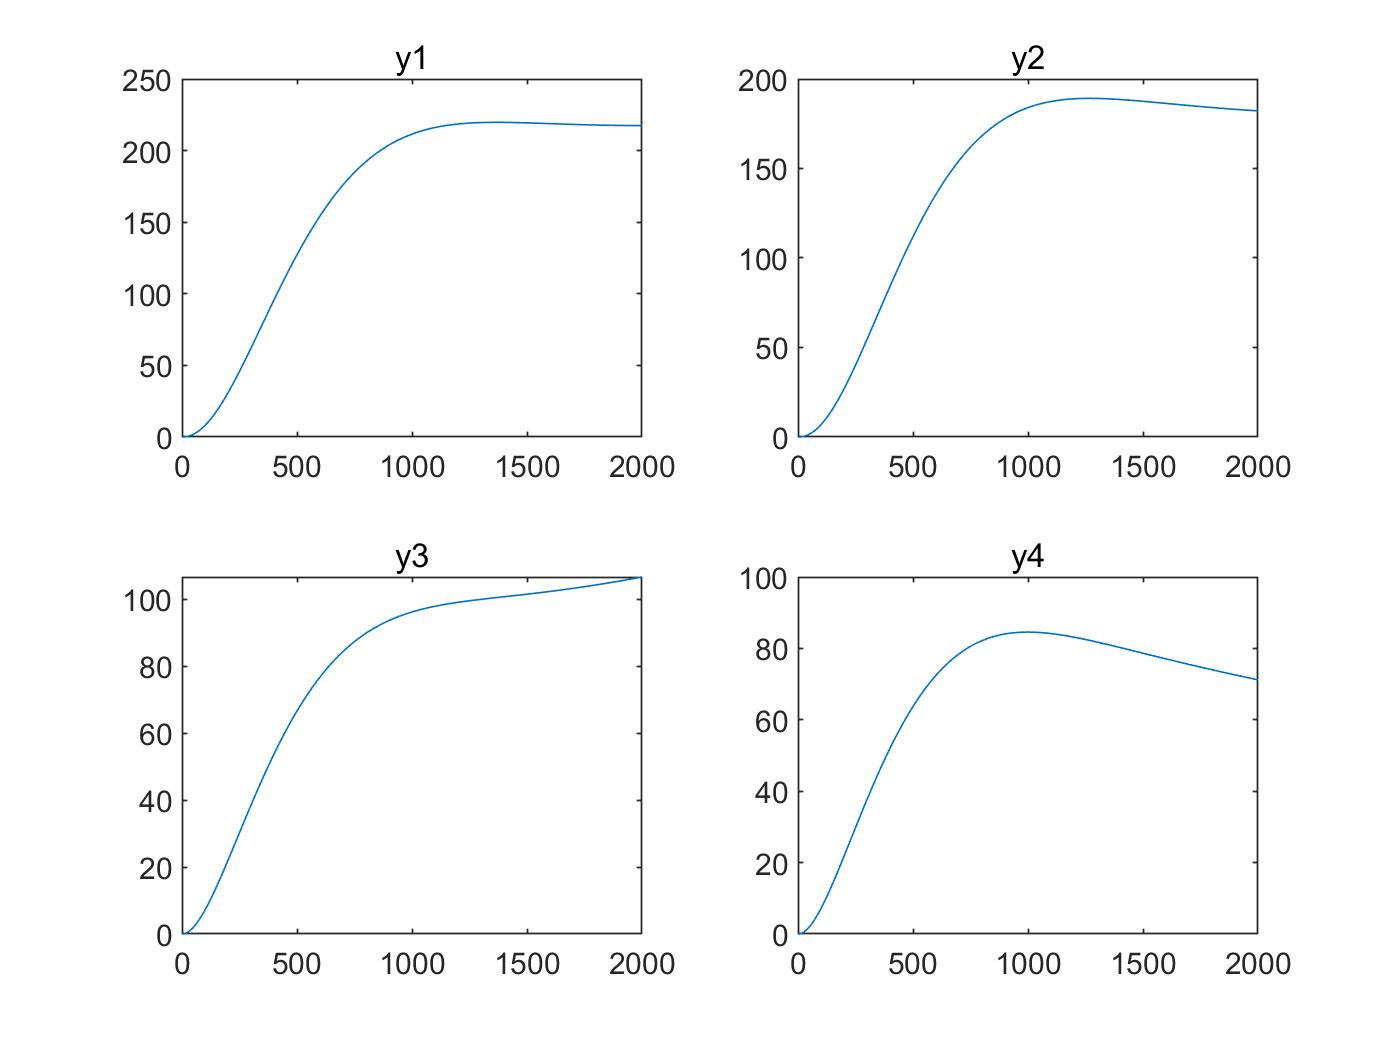

figure
subplot(2,2,1)
plot(t,y(1,:))
title('y1')
subplot(2,2,2)
plot(t,y(2,:))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

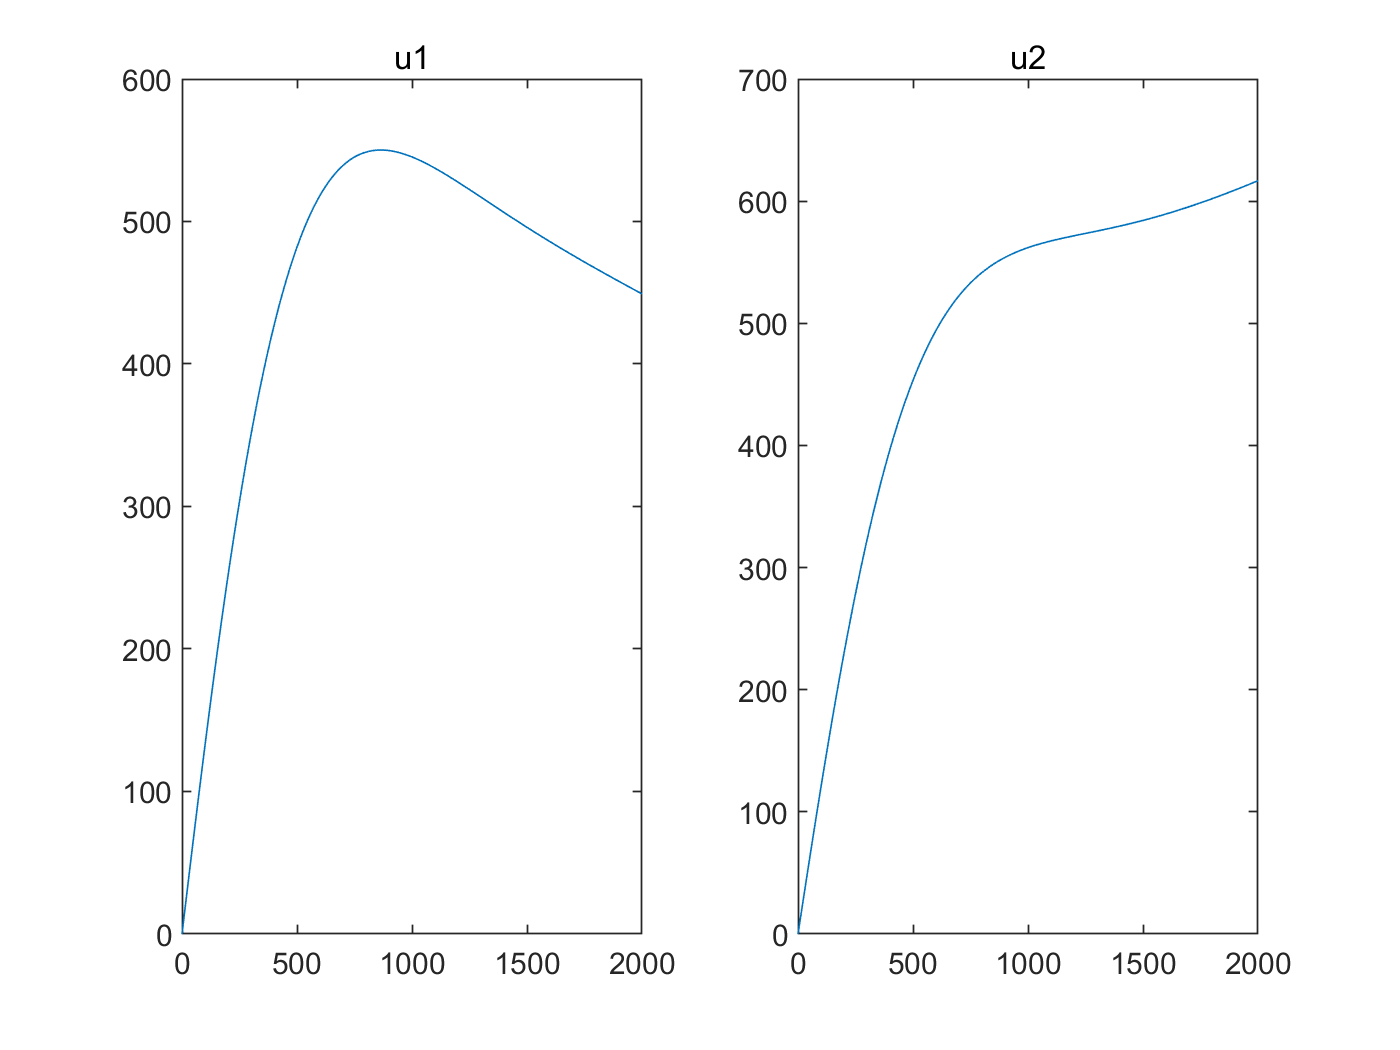

figure;
subplot(1,2,1)
plot(t,u(1,:))
title('u1')
subplot(1,2,2)
plot(t,u(2,:))
title('u2')

R = chol(Hu)
z(p)=D\(L\-g(p))% back substitution

%%有约束线性MPC算法设计，考虑前馈（扰动）和输入的变化率,真正体现MPC的优势的地方在于对约束的处理
%有约束意味着没有解析解（如果是硬约束）
%对input进行约束，input本身和其变化率
%闭环测试线性MPC，对线性离散系统
t0 = 0.0; % [s] Initial time
t_final = 2000; % [s] Final time
Ts = 4; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
N_pre=10;
u_min=0;
u_max=500;
u_delta_min=-2;
u_delta_max=2;
x = zeros(num_x,N);
y = zeros(num_y,N);
z = zeros(num_z,N);
u = zeros(num_u,N);
x0=zeros(4,1);
x(:,1) = x0;
xk=x0;
rk=200*ones(N_pre*num_z,1);%z1,z2 ref
dk=ones(N_pre*num_d,1);%d1,d2 ref
uk=zeros(num_u,1);%d1,d2 ref
for k = 1:N-1
yk=Css*xk; % Sensor function
zk=Czss*xk; % Output function
%uk=MPCcompute_linear(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_analytical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
%uk=MPCcompute_linear_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,N_pre);
uk=MPCcompute_linear_inputCons_qp_numerical(rk,xk,dk,uk,Ad,Bd,Bd_d,Czss,u_min,u_max,u_delta_min,u_delta_max,N_pre);
xk=Ad*xk+Bd*uk+Bd_d*dk(1:num_d);
x(:,k+1)=xk;
y(:,k+1)=yk;
z(:,k+1)=zk;
u(:,k+1)=uk;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because the objective function

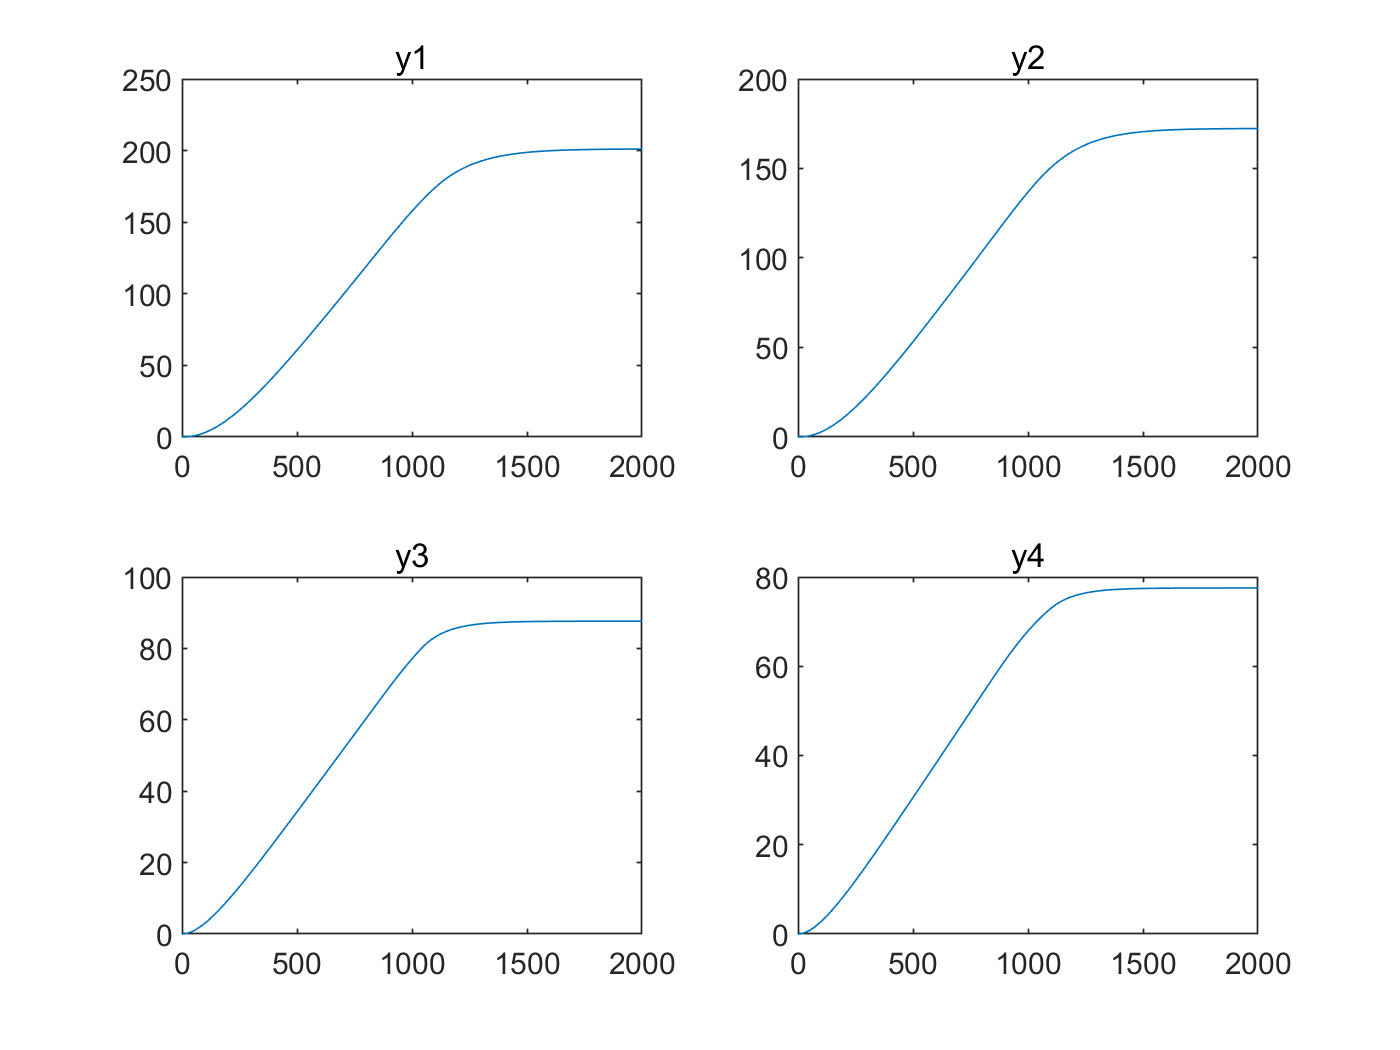

figure
subplot(2,2,1)
plot(t,y(1,:))
title('y1')
subplot(2,2,2)
plot(t,y(2,:))
title('y2')
subplot(2,2,3)
plot(t,y(3,:))
title('y3')
subplot(2,2,4)
plot(t,y(4,:))
title('y4')

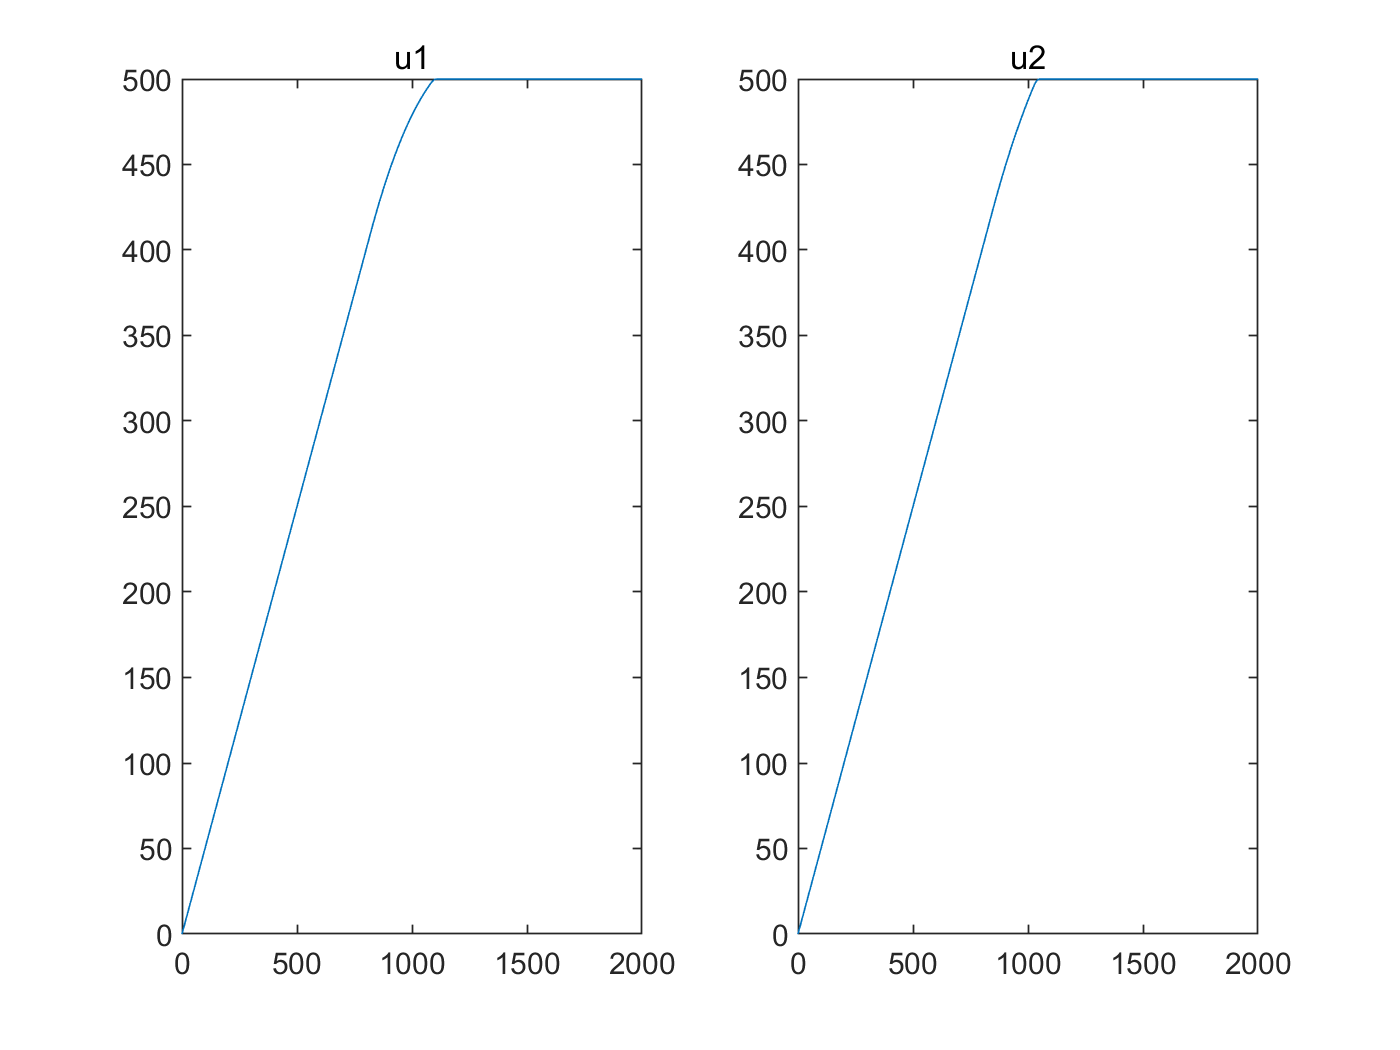

figure;
subplot(1,2,1)
plot(t,u(1,:))
title('u1')
subplot(1,2,2)
plot(t,u(2,:))
title('u2')

%ex3.6 计算马尔可夫参数，也就是脉冲响应参数
H_0=Dss;
H_1=Css*Bd

H_1 =     0.0047    0.0001
    0.0001    0.0041
         0    0.0062
    0.0057         0


H_2=Css*Ad^1*Bd

H_2 =     0.0045    0.0003
    0.0003    0.0040
         0    0.0060
    0.0055         0


H_3=Css*Ad^2*Bd

H_3 =     0.0044    0.0005
    0.0005    0.0039
         0    0.0058
    0.0053         0


H_4=Css*Ad^3*Bd

H_4 =     0.0043    0.0007
    0.0007    0.0038
         0    0.0056
    0.0051         0


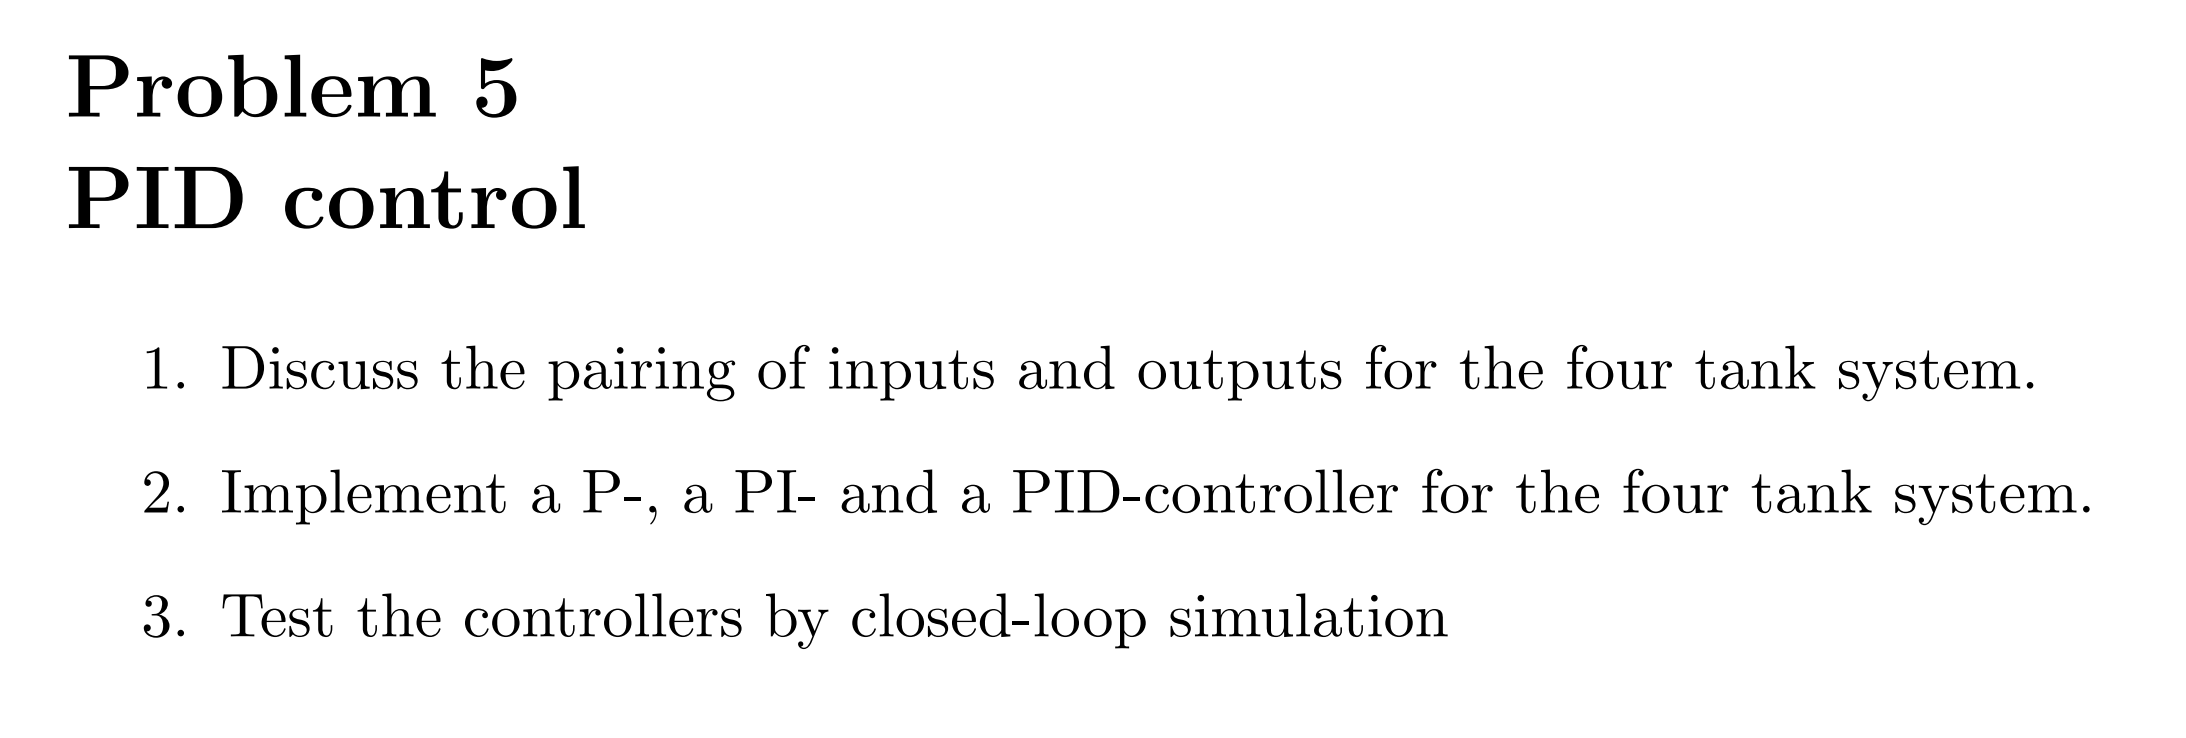

u1->x1,x2,x4

u2->x2,x3

%水箱系统明显是一个MOMO系统，并且还存在着耦合，所以我们需要设计解耦矩阵，然后进行pid的调节
%首先我们需要求出四个传递函数
[num_c_F1,den_c_F1]=ss2tf(Ass,Bss,Css,Dss,1)

num_c_F1 =          0    0.0012    0.0000    0.0000    0.0000
         0         0    0.0000    0.0000    0.0000
         0         0         0         0         0
         0    0.0014    0.0000    0.0000    0.0000


den_c_F1 =     1.0000    0.0325    0.0004    0.0000    0.0000


[num_c_F2,den_c_F2]=ss2tf(Ass,Bss,Css,Dss,2)

num_c_F2 =          0         0    0.0000    0.0000    0.0000
         0    0.0011    0.0000    0.0000    0.0000
         0    0.0016    0.0000    0.0000    0.0000
         0         0         0         0         0


den_c_F2 =     1.0000    0.0325    0.0004    0.0000    0.0000


G_c_F1_y1=tf(num_c_F1(1,:),den_c_F1)%same to con->dis

G_c_F1_y1 =
 
    0.001184 s^3 + 3.039e-05 s^2 + 2.585e-07 s + 7.28e-10
  ----------------------------------------------------------
  s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
Continuous-time transfer function.



G_c_F1_y2=tf(num_c_F1(2,:),den_c_F1)

G_c_F1_y2 =
 
           1.355e-05 s^2 + 2.157e-07 s + 8.425e-10
  ----------------------------------------------------------
  s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
Continuous-time transfer function.



G_c_F2_y1=tf(num_c_F2(1,:),den_c_F2)

G_c_F2_y1 =
 
           1.427e-05 s^2 + 2.373e-07 s + 9.707e-10
  ----------------------------------------------------------
  s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
Continuous-time transfer function.



G_c_F2_y2=tf(num_c_F2(2,:),den_c_F2)

G_c_F2_y2 =
 
    0.001052 s^3 + 2.661e-05 s^2 + 2.223e-07 s + 6.128e-10
  ----------------------------------------------------------
  s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
Continuous-time transfer function.




[num_d_F1,den_d_F1]=ss2tf(Ad,Bd,Css,Dss,1)

num_d_F1 =          0    0.0047   -0.0135    0.0131   -0.0042
         0    0.0001   -0.0001   -0.0001    0.0001
         0         0         0         0         0
         0    0.0057   -0.0165    0.0160   -0.0052


den_d_F1 =     1.0000   -3.8719    5.6219   -3.6279    0.8779


[num_d_F2,den_d_F2]=ss2tf(Ad,Bd,Css,Dss,2)

num_d_F2 =          0    0.0001   -0.0001   -0.0001    0.0001
         0    0.0041   -0.0120    0.0116   -0.0037
         0    0.0062   -0.0180    0.0175   -0.0056
         0         0         0         0         0


den_d_F2 =     1.0000   -3.8719    5.6219   -3.6279    0.8779


G_d_F1_y1=tf(num_d_F1(1,:),den_d_F1,Ts)%same to con->dis

G_d_F1_y1 =
 
  0.004671 z^3 - 0.01354 z^2 + 0.01309 z - 0.004215
  -------------------------------------------------
   z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F1_y2=tf(num_d_F1(2,:),den_d_F1,Ts)

G_d_F1_y2 =
 
  0.000106 z^3 - 0.0001017 z^2 - 0.0001014 z + 9.732e-05
  ------------------------------------------------------
      z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F2_y1=tf(num_d_F2(1,:),den_d_F2,Ts)

G_d_F2_y1 =
 
  0.0001117 z^3 - 0.0001068 z^2 - 0.0001071 z + 0.0001024
  -------------------------------------------------------
      z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
Sample time: 4 seconds
Discrete-time transfer function.



G_d_F2_y2=tf(num_d_F2(2,:),den_d_F2,Ts)

G_d_F2_y2 =
 
  0.004149 z^3 - 0.01203 z^2 + 0.01164 z - 0.00375
  ------------------------------------------------
   z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
Sample time: 4 seconds
Discrete-time transfer function.




G_MIMO=[G_d_F1_y1,G_d_F1_y2;G_d_F2_y1,G_d_F2_y2]

G_MIMO =
 
  From input 1 to output...
       0.004671 z^3 - 0.01354 z^2 + 0.01309 z - 0.004215
   1:  -------------------------------------------------
        z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
       0.0001117 z^3 - 0.0001068 z^2 - 0.0001071 z + 0.0001024
   2:  -------------------------------------------------------
           z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
  From input 2 to output...
       0.000106 z^3 - 0.0001017 z^2 - 0.0001014 z + 9.732e-05
   1:  ------------------------------------------------------
           z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
       0.004149 z^3 - 0.01203 z^2 + 0.01164 z - 0.00375
   2:  ------------------------------------------------
        z^4 - 3.872 z^3 + 5.622 z^2 - 3.628 z + 0.8779
 
Sample time: 4 seconds
Discrete-time transfer function.



G_c_MIMO=[G_c_F1_y1,G_c_F1_y2;G_c_F2_y1,G_c_F2_y2]

G_c_MIMO =
 
  From input 1 to output...
         0.001184 s^3 + 3.039e-05 s^2 + 2.585e-07 s + 7.28e-10
   1:  ----------------------------------------------------------
       s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
                1.427e-05 s^2 + 2.373e-07 s + 9.707e-10
   2:  ----------------------------------------------------------
       s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
  From input 2 to output...
                1.355e-05 s^2 + 2.157e-07 s + 8.425e-10
   1:  ----------------------------------------------------------
       s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
         0.001052 s^3 + 2.661e-05 s^2 + 2.223e-07 s + 6.128e-10
   2:  ----------------------------------------------------------
       s^4 + 0.03255 s^3 + 0.0003949 s^2 + 2.117e-06 s + 4.23e-09
 
Continuous-time transfer function.



%我们使用静态解耦矩阵计算
G0_MIMO=dcgain(G_MIMO)

G0_MIMO =     0.1721    0.1992
    0.2295    0.1449


G0_c_11=dcgain(cell2mat(G_c_F1_y1.Numerator),cell2mat(G_c_F1_y1.Denominator))

G0_c_11 = 0.1721

G0_c_12=dcgain(cell2mat(G_c_F1_y2.Numerator),cell2mat(G_c_F1_y2.Denominator))

G0_c_12 = 0.1992

G0_c_21=dcgain(cell2mat(G_c_F2_y1.Numerator),cell2mat(G_c_F2_y1.Denominator))

G0_c_21 = 0.2295

G0_c_22=dcgain(cell2mat(G_c_F2_y2.Numerator),cell2mat(G_c_F2_y2.Denominator))

G0_c_22 = 0.1449

G0_c_MIMO=dcgain(G_c_MIMO)%just for test

G0_c_MIMO =     0.1721    0.1992
    0.2295    0.1449


%计算相对增益矩阵，判断是否需要进行解耦操作
F0=G0_MIMO(1,2)*G0_MIMO(2,1)/(G0_MIMO(1,1)*G0_MIMO(2,2))

F0 = 1.8333

T0_11=1/(1-F0)

T0_11 = -1.2000

T0_12=-F0/(1-F0)

T0_12 = 2.2000

T0_21=-F0/(1-F0)

T0_21 = 2.2000

T0_22=1/(1-F0)

T0_22 = -1.2000

%计算静态解耦矩阵
G0_11=G0_MIMO(1,1);
G0_12=G0_MIMO(1,2);
G0_21=G0_MIMO(2,1);
G0_22=G0_MIMO(2,2);
D0=(1/(G0_11*G0_22-G0_12*G0_21))*[G0_22*G0_11,-G0_12*G0_22;-G0_21*G0_11,G0_11*G0_22]

D0 =    -1.2000    1.3887
    1.9010   -1.2000


%TEST 解耦矩阵
G_MIMO_decop=D0*G_MIMO

G_MIMO_decop =
 
  From input 1 to output...
       -0.00545 z^7 + 0.03721 z^6 - 0.1088 z^5 + 0.1769 z^4 - 0.1725 z^3 + 0.1009 z^2 - 0.03279 z + 0.004566
   1:  -----------------------------------------------------------------------------------------------------
           z^8 - 7.744 z^7 + 26.24 z^6 - 50.79 z^5 + 61.46 z^4 - 47.59 z^3 + 23.03 z^2 - 6.37 z + 0.7708
 
       0.008746 z^7 - 0.05948 z^6 + 0.1734 z^5 - 0.2807 z^4 + 0.2727 z^3 - 0.159 z^2 + 0.05147 z - 0.007143
   2:  ----------------------------------------------------------------------------------------------------
          z^8 - 7.744 z^7 + 26.24 z^6 - 50.79 z^5 + 61.46 z^4 - 47.59 z^3 + 23.03 z^2 - 6.37 z + 0.7708
 
  From input 2 to output...
       0.005635 z^7 - 0.03841 z^6 + 0.1122 z^5 - 0.1821 z^4 + 0.1773 z^3 - 0.1036 z^2 + 0.03361 z - 0.004675
   1:  -----------------------------------------------------------------------------------------------------
           z^8 - 7.744 z^7 + 26.24 z^6 - 50.79 z^5 + 61.46 z^4

G0_MIMO_decop=dcgain(G_MIMO_decop)

G0_MIMO_decop =     0.1116   -0.0376
    0.0516    0.2038


F0_decop=G0_MIMO_decop(1,2)*G0_MIMO_decop(2,1)/(G0_MIMO_decop(1,1)*G0_MIMO_decop(2,2))

F0_decop = -0.0853

T0_11_decop=1/(1-F0_decop)

T0_11_decop = 0.9214

T0_12_decop=-F0_decop/(1-F0_decop)

T0_12_decop = 0.0786

T0_21_decop=-F0_decop/(1-F0_decop)

T0_21_decop = 0.0786

T0_22_decop=1/(1-F0_decop)

T0_22_decop = 0.9214

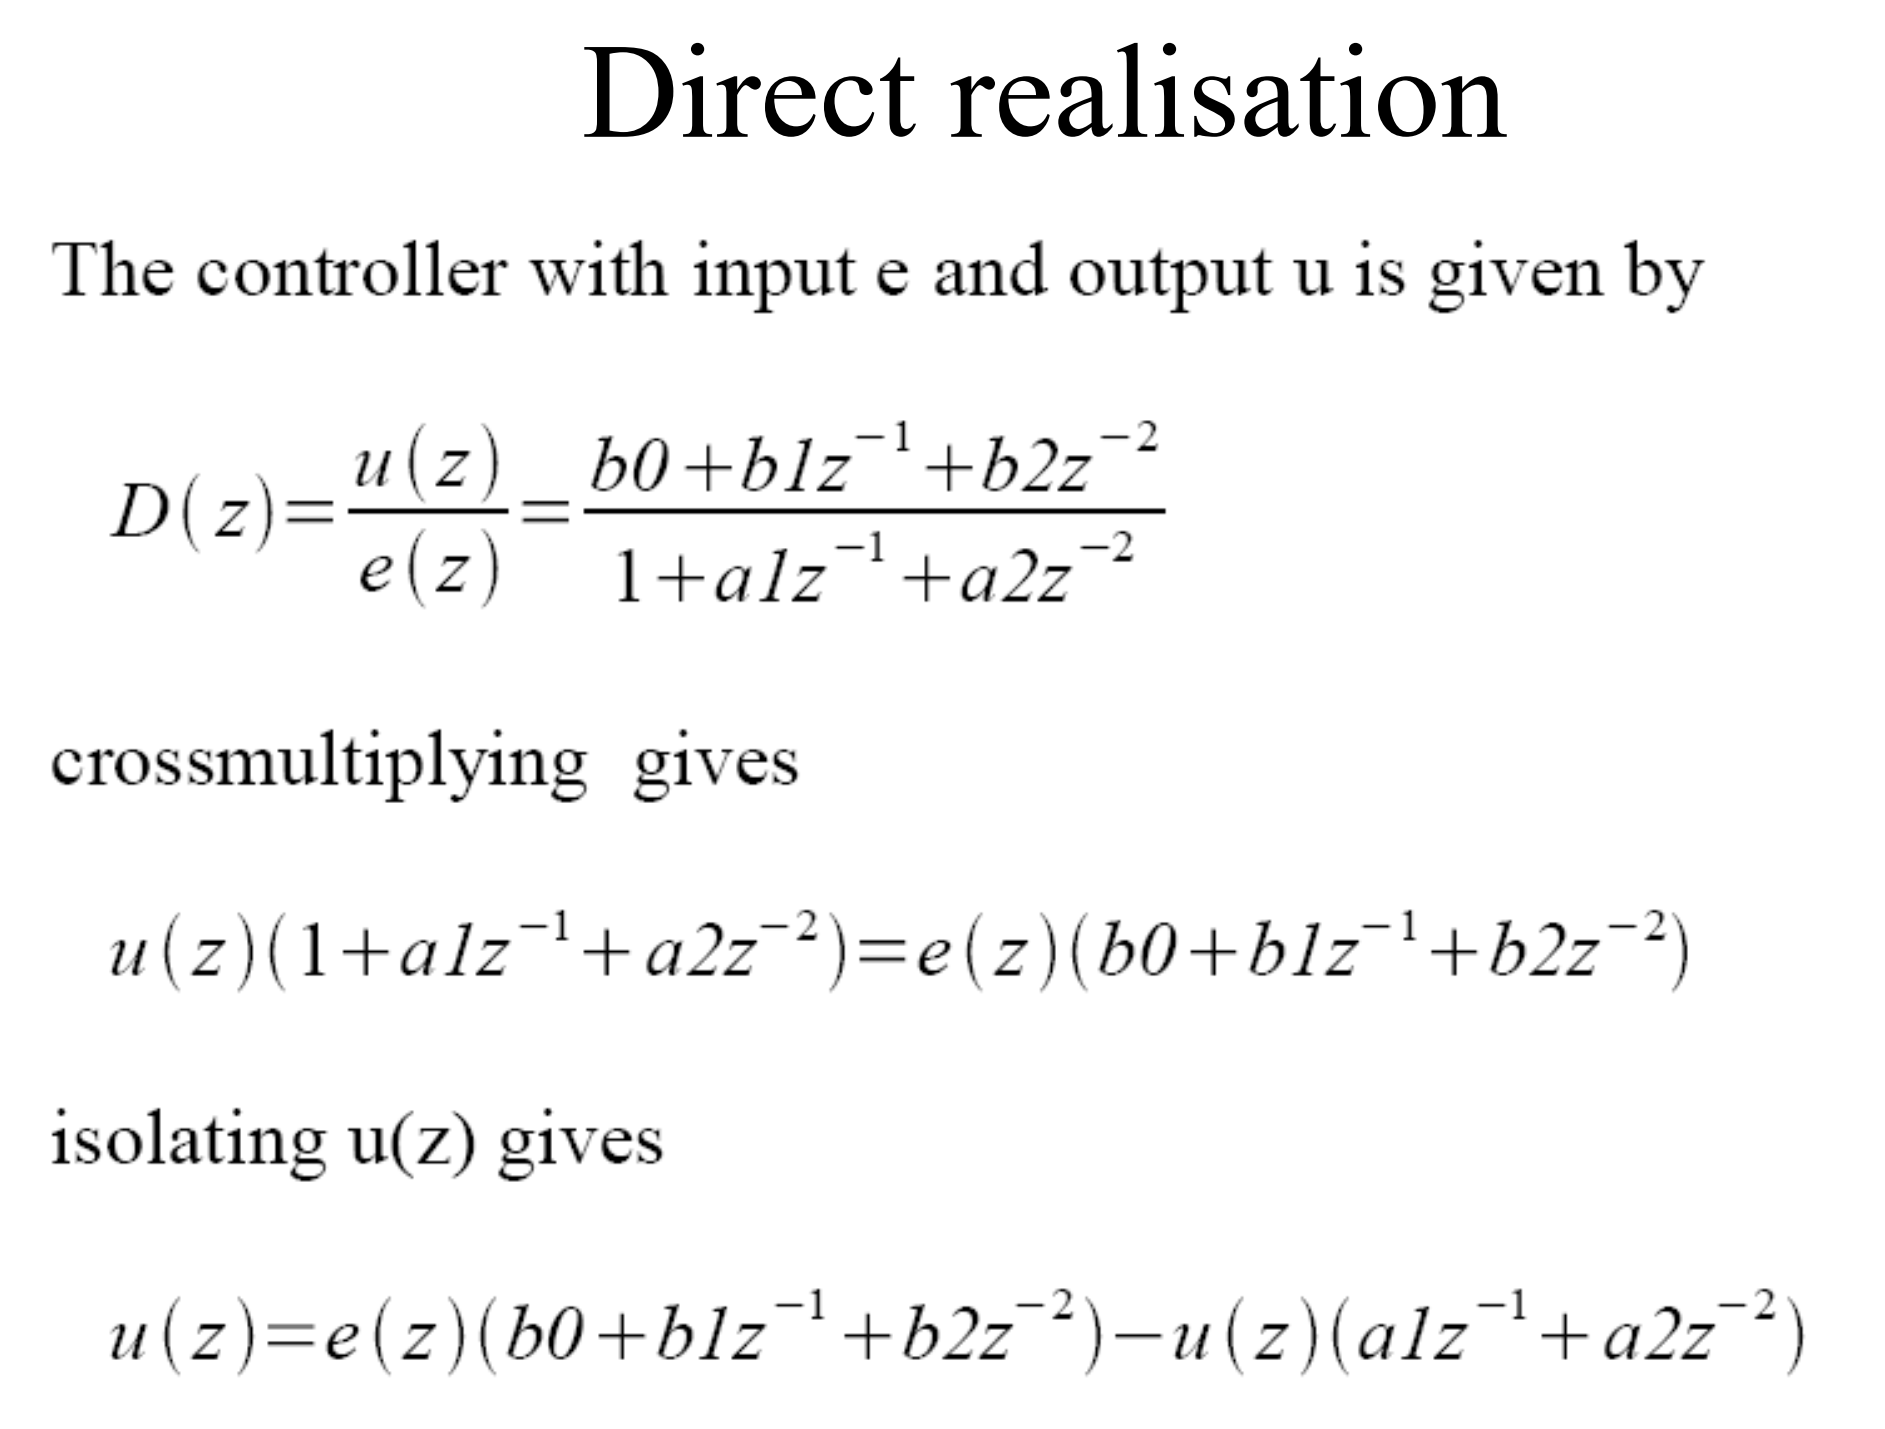

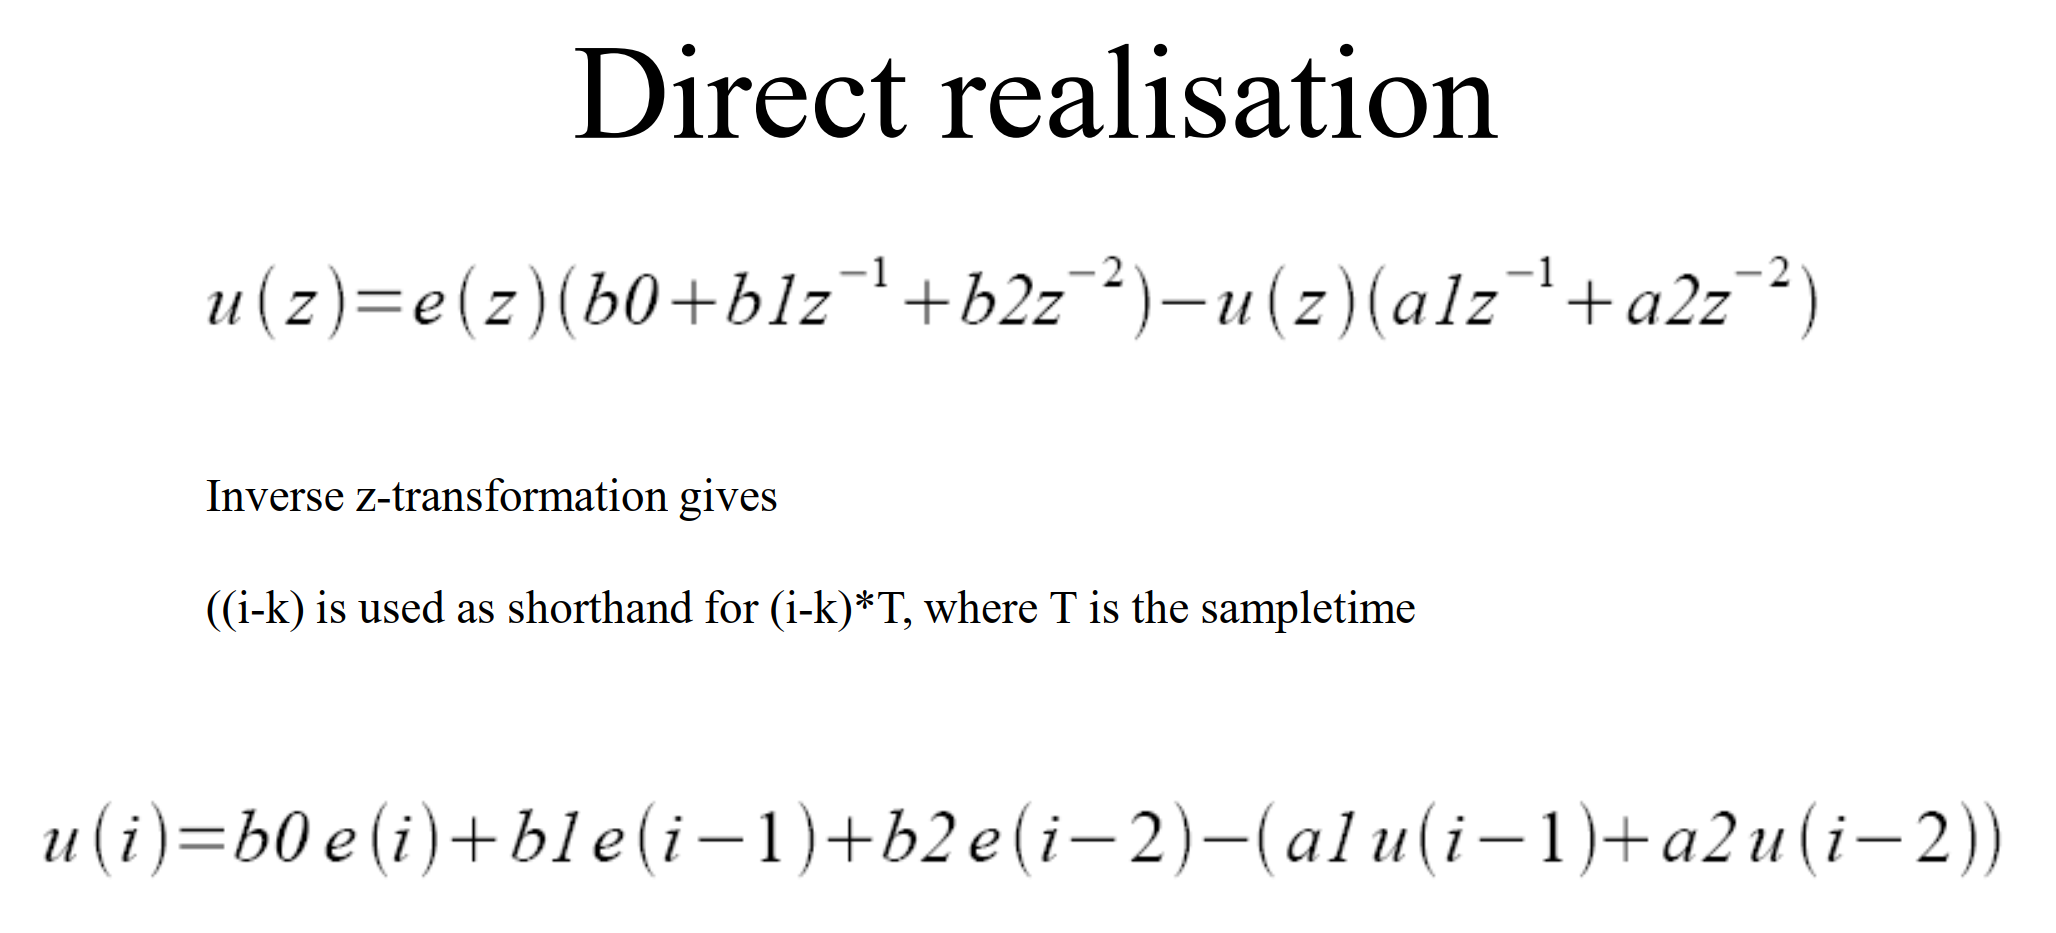


ts=4;  
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
F1 = 300; % [cm3/s] Flow rate from pump 1
F2 = 300; % [cm3/s] Flow rate from pump 2
F3 = 250;
F4 = 250;
x0 = [m10; m20; m30; m40];

u1_1=0.0;u1_2=0.0;u1_3=0.0;u1_4=0.0;u1_5=0.0;%输入向量 的初始状态，这里使用线性模型，与模型离散化后的传递函数的z阶次有关
u2_1=0.0;u2_2=0.0;u2_3=0.0;u2_4=0.0;u2_5=0.0;
y1_1=0.0;y1_2=0.0;y1_3=0.0;y1_4=0.0;y1_5=0.0%输出的初始状态
y2_1=0.0;y2_2=0.0;y2_3=0.0;y2_4=0.0;y2_5=0.0%输出的初始状态
[num_11,den_11]=tfdata(G_MIMO(1,1),'v')
[num_12,den_12]=tfdata(G_MIMO(1,1),'v')
[num_21,den_21]=tfdata(G_MIMO(1,1),'v')
[num_22,den_22]=tfdata(G_MIMO(1,1),'v')
x_pid=[0,0,0]';%PID的3个参数Kp Ki Kd组成的数组
error_1=0;%初始误差
t_final = 20*60; % [s] Final time
t = [t0:ts:t_final]'; % [s] Sample instants
N = length(t);

nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;

for k=1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
    z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
    [u_pid,I]=MIMO_Decop_PID([0;0],y())
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
    u_50_F1(:,k),d(:,k),p);
    x(:,k+1) = Xk(end,:)';
    T = [T; Tk];
    X = [X; Xk];
end

for k=1:N-1
    y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
    z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
    [u_pid,I]=MIMO_Decop_PID([0;0],y())
    [Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
    u_50_F1(:,k),d(:,k),p);
    x(:,k+1) = Xk(end,:)';
    T = [T; Tk];
    X = [X; Xk];
end